# Robust Maneuver Planning for Autonomous Vehicles

# Model Initialisation

To prepare the simulation, different parameters can be set by calling the function [prepare_simulation](matlab:open('./prepare_simulation.m')). The arguments can be modified to set the:

- Road geometry 

- Number of other vehicles (excluding ego vehicle)

- Vehicles' initial states (position, velocity) 

- Planner mode (rule-based design, formal design)

- Lateral control mode (Lateral Stanley control, Pure Pursuit control)

- Time horizon considered for planning a maneuver

- Uncertainties for estimating the other vehicles' states

When calling the function without any arguments, the predefined default options will be set. The Simulink model will be prepared accordingly.

To run the simulation, the function [run_simulation](matlab:open('./run_simulation.m')) can be called. Therfor, the simulation time can be passed as an argument.

Furthermore, predefined [DrivingScenarios](matlab:open('./DrivingScenarios.m')) using either the rule-based planner or the formally designed planner can be selected and started by running the respective section.

# Simulink Model

## Main Model

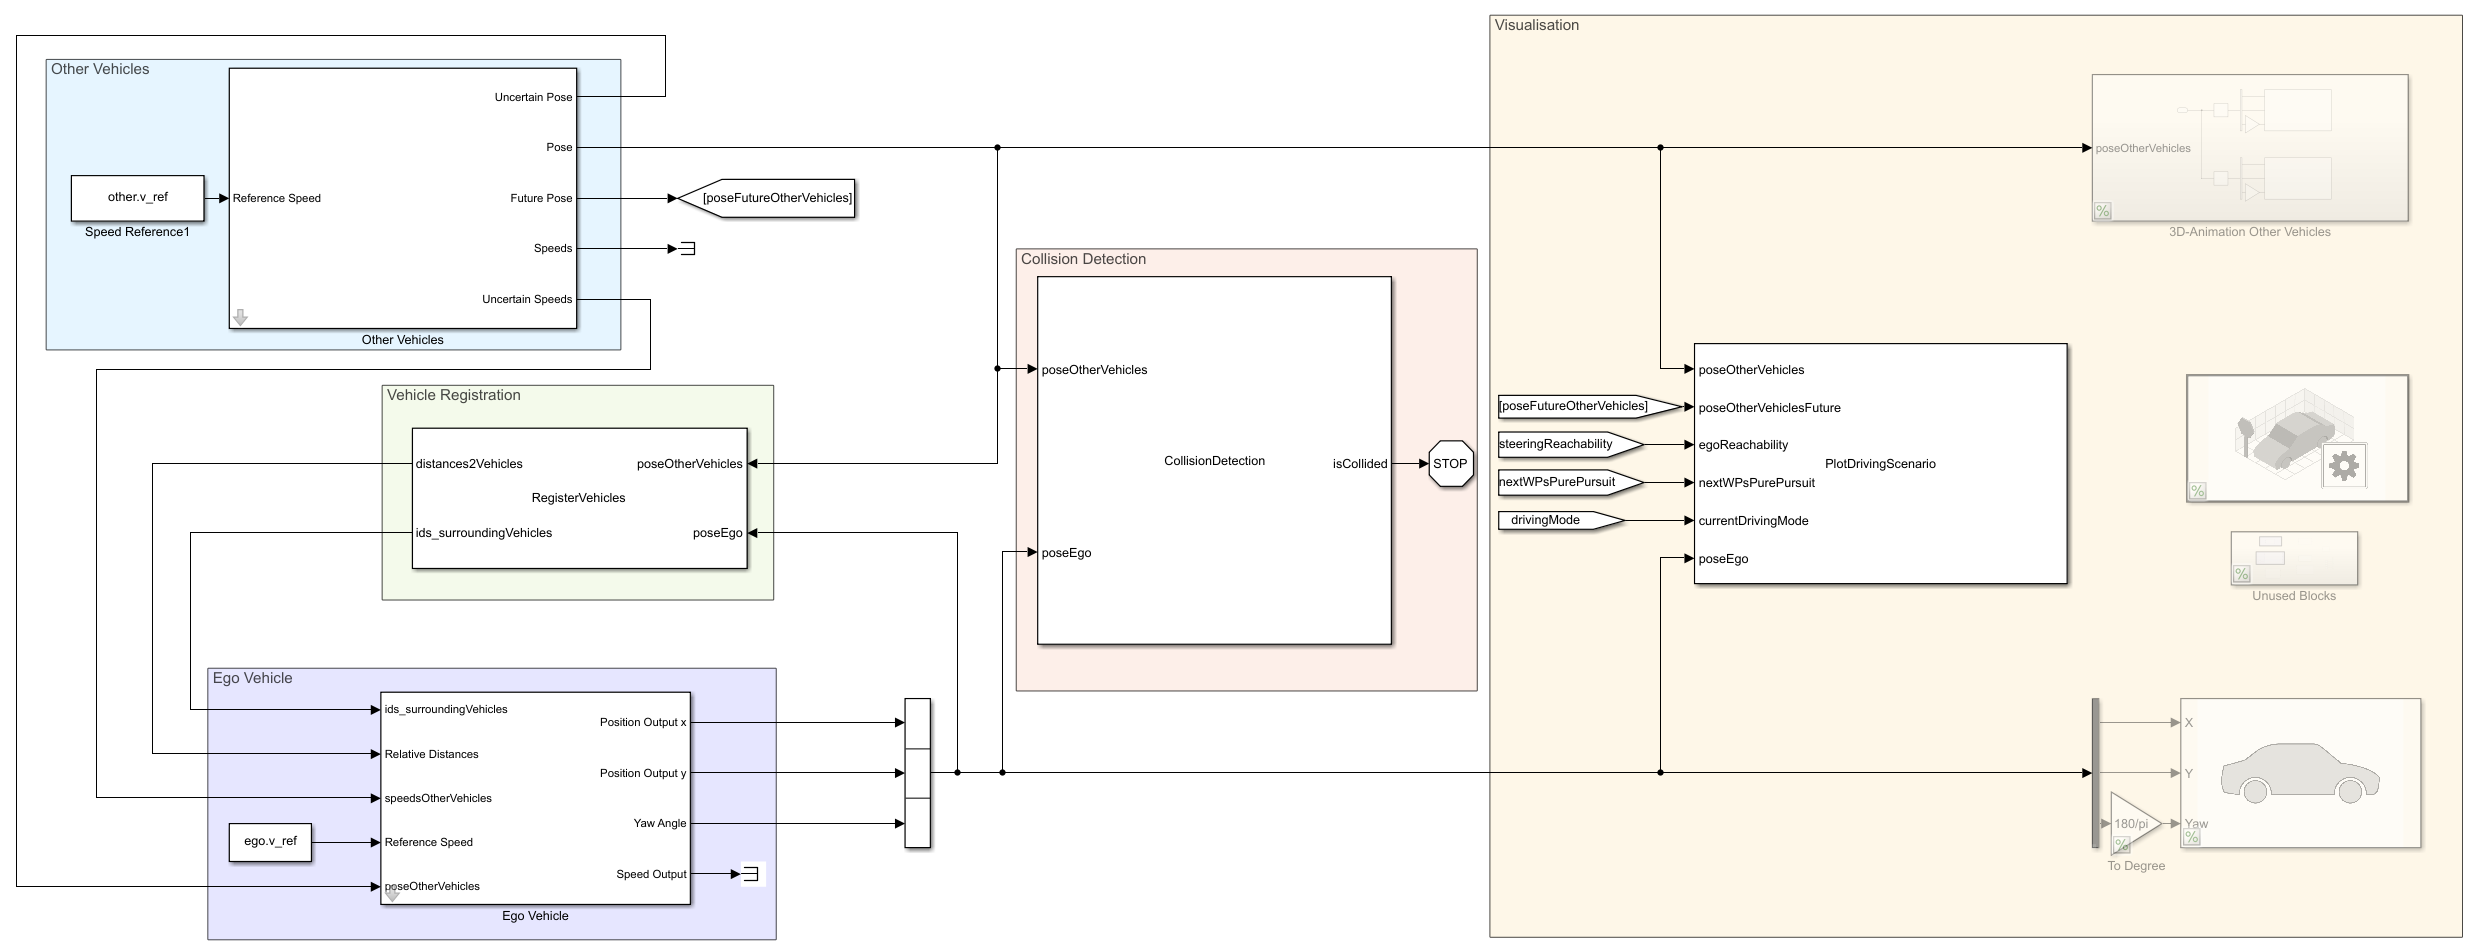

The main model contains the following components:

### Ego Vehicle (Violet)

Model of the ego vehicle. 

### Other Vehicles (Cyan)

Model of the other vehicles.

### Vehicle Registration (Green)

Register the closest vehicles next to the ego vehicles. Those are the closest vehicle behind and in front of the ego vehicle on the same lane and on the opposite lane. The closesest vehicle in front of the ego vehicle which is also on the same lane is defined as the leading vehicle

### Collision Detection (Red)

Detect if the ego vehicle has collided with one of the other vehicles. If so, stop the simulation

### Visualisation (Yellow)

The driving scenario will be visualised in 2D using the plot function. Optionally, the scenario can also be visualised in 3D by uncommenting the necessary blocks on the right next to the PlotDrivingScenario block.

## Ego Vehicle Model

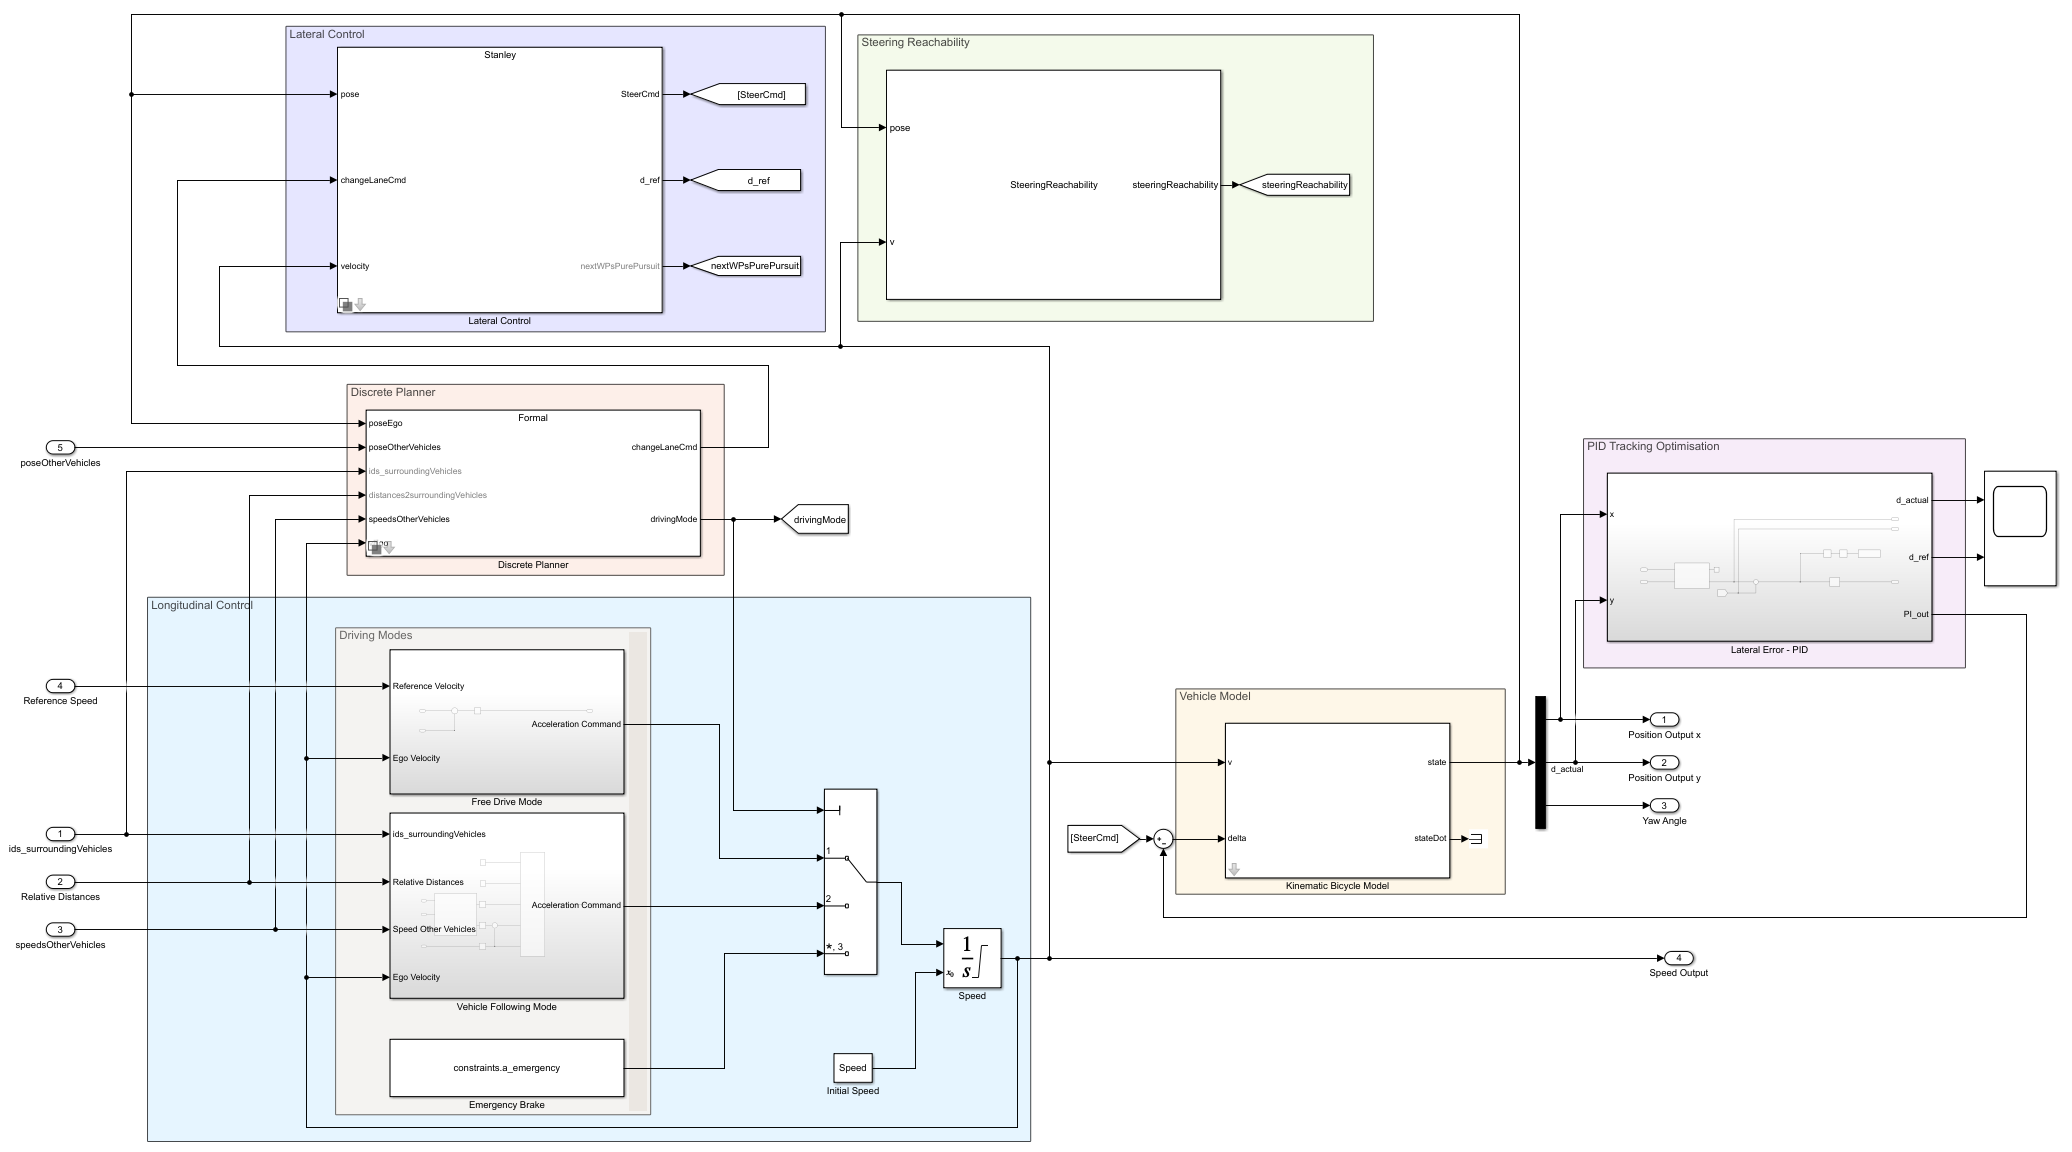

The ego vehicle model contains the following components:

### Vehicle Model (Yellow)

The kinematic bicycle model is used as the model for the ego vehicle.

### Longitudinal Control (Cyan)

Longitudinal control according to the double integrator model.

### Driving Modes (Grey)

For longitudinal control there exist three different driving modes:

- Free Drive

- Vehicle Following

- Emergency Brake

### Lateral Control (Violet)

For the lateral control of the ego vehicle there is a choice between:

- Lateral Stanley Controller

- Pure Pursuit Controller

### Discrete Planner (Red)

The discrete planner makes decision about what driving mode to use and whether to change the current lane or not. Also the parameters for a possible lane changing trajectory are set. For the planner there is the choice between a:

- Rule-based design

- Formal design

### PID Tracking Optimisation (Magenta)

A tuned PID controller is used for a better tracking performance of the chosen reference trajectory.

# Kinematic Bicycle Model

The kinematic bicycle model can be used to simulate simplified car-like vehicle dynamics. The coordinate origin of this model is defined at the center of the bicycle's rear axle, which defines the body coordinate system $x_{b}$ and $y_{b}$. For the Simulink block, the used inputs that are the vehicle's velocity $v$ in $\frac{m}{s}$ and the steering angle $\delta$ in rad. The model outputs the state $[x, y, \theta ]$ of the model, which is the vehicle's pose.

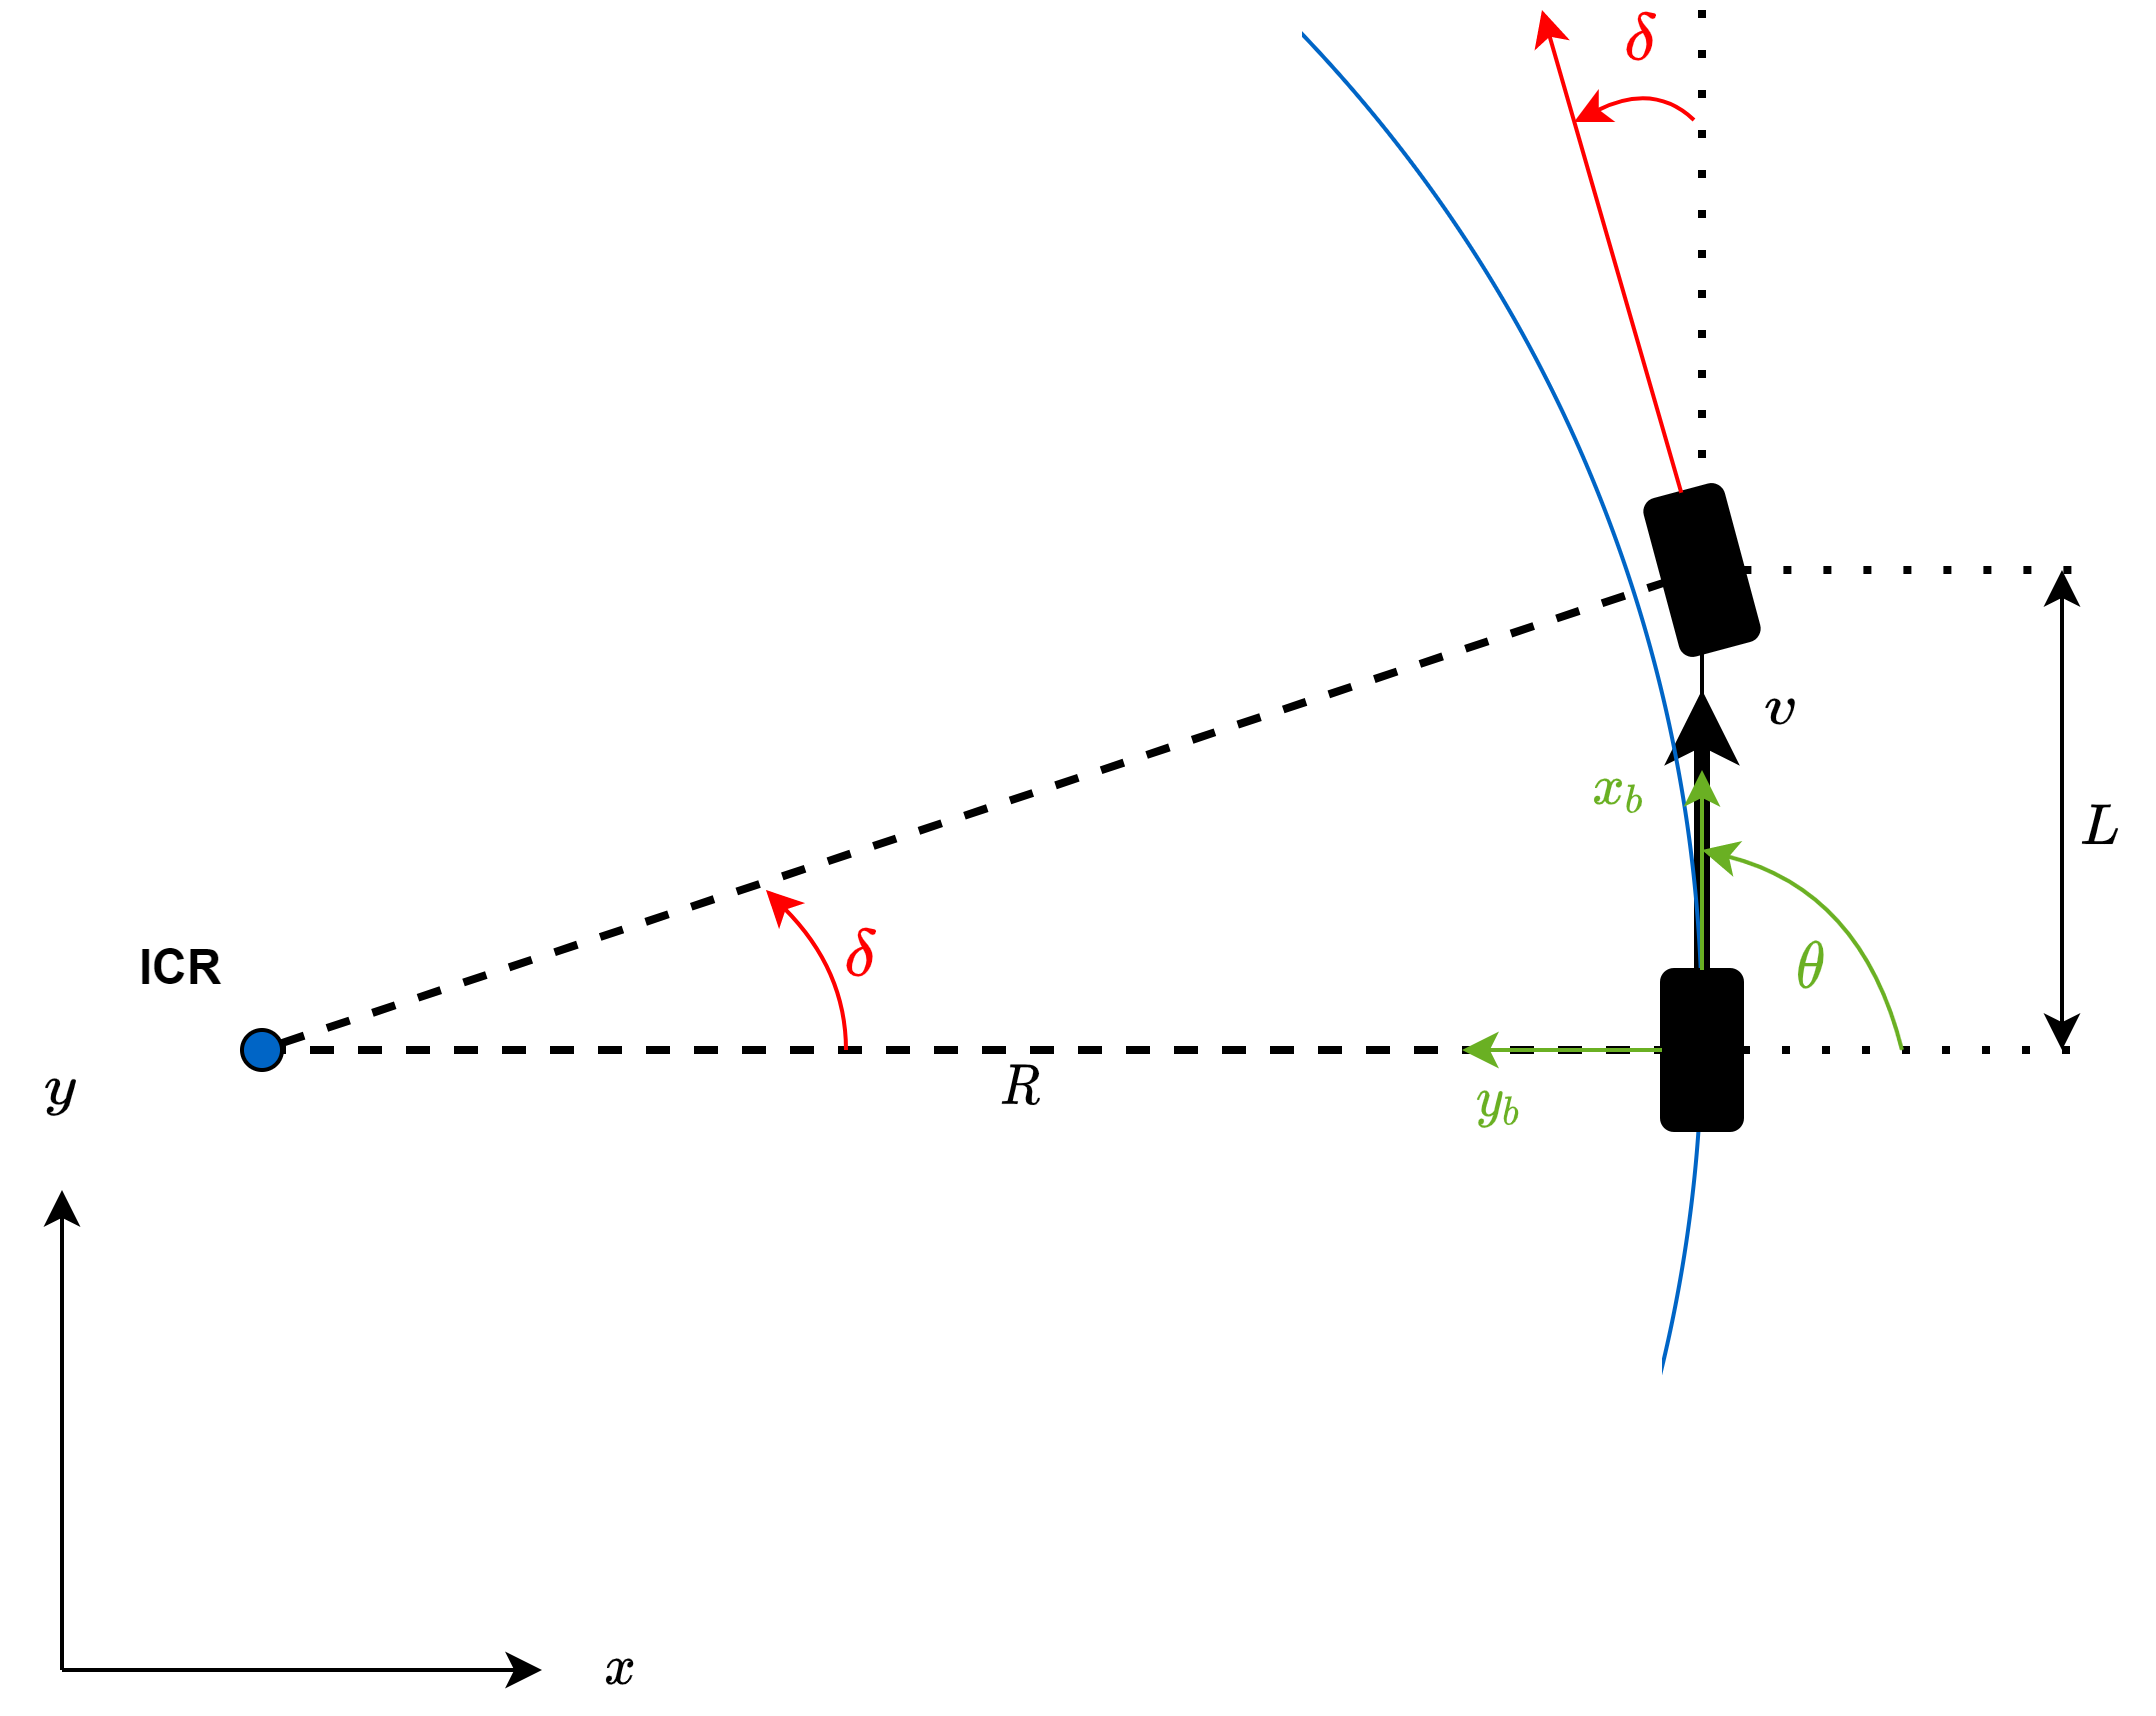

### Equations of motion

The origin of the body coordinate system moves along a circular path. The circle's center is the Instantaneous Center of Rotation (ICR) and has the radius $R$. Thus the eqations of motion are: 


$$\dot x = v \cos(\theta) \\
\dot y = v \sin(\theta) \\ 
\dot \theta = \frac{v}{L}tan(\delta)$$


The maximum steering angle $\delta_{max}$  and the wheel base $L$ limit the radius $R$ or respectively the curvature $\kappa$:


$$R_{min} = \frac{L}{tan(\delta_{max})} \\
\kappa_{max} = \frac{1}{R_{min}}  = \frac{tan(\delta_{max})}{L} \\ 
$$


### References

[https://www.mathworks.com/help/robotics/ref/bicyclekinematicmodel.html](https://www.mathworks.com/help/robotics/ref/bicyclekinematicmodel.html)

Corke, Peter I. *Robotics, Vision and Control: Fundamental Algorithms in MATLAB*. Springer, 2011.

# Constraints and Boundaries

For this model the following boundaries and constraints are considered:

## Road Boundaries

The road is bounded by its length and width, with $w_{lane} = 3.7$ being the lane width and $s$ and $d$ being the Frenet coordinates of the road:


$$s \in [0, \ s_{max}] \\
d \in [- \frac{1}{2}w_{lane},  \ \frac{3}{2}w_{lane}]$$


## Kinematic Constraints

The vehicles' kinematics are constrained by limiting the velocity $v$ and the acceleration $a$. For an emergency case the acceleration can drop to $a_{emergency}$. Otherwise it should be $a_{nom}$. For Only forward motion is allowed:


$$v \in [0, \ v_{max}] \\
a_{nom} \in [a_{min}, \ a_{max}]$$


## Steering Constraints

In real systems the steering angle $\delta$ is usually limeted mechanically:


$$\delta \in [-\delta_{max}, \ \delta_{max}] \\
$$


# Longitudinal Control

There exist the following driving modes:

## Free Drive

The vehicle accelerates until the predifined reference velocity $v_{ref}$ is reached. The acceleration command is the difference between the reference velocity $v_{ref}$ and the current velocity $v$. 

## Vehicle Following

The goal of this driving mode is to keep a safe distance $\Delta s_{safe}$ between the ego vehicle and the leading vehicle. To calculate the acceleration command, a tuned PID controller is used with the current distance $\Delta s$ and the desired disctance $\Delta s_{safe}$ between the two vehicles.

## Emergency Brake

The acceleration command for an emergency brake is the constant acceleration $a_{emergency}$.

# Lateral Control

In this Model one of two lateral controllers can be chosen. Using a Simulink Variant Subsystem block, either the Pure Pursuit controller or the Lateral Stanley controller can be selected. For Pure Pursuit, reference waypoints on the desired path need to be generated. The Lateral Stanley controller on the other hand needs a reference pose on the path according to its front axle at every time step. Therefore the MATLAB Systems [PurePursuitWPGenerator](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner\PurePursuitWPGenerator.m')) and [StanleyPoseGenerator](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner\StanleyPoseGenerator.m')) were created. Both of them are a subclass of the [LocalTrajectoryPlanner](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner\LocalTrajectoryPlanner.m')).

## Pure Pursuit Controller

Pure Pursuit is an algorithm that is used for path tracking. It takes the vehicle's current pose $[x, y, \theta ]$ and the next waypoints' coordinates $[x, y]$ as an input. The figure shows the desired path defined by different waypoints (WPs) and the vehicle's current position and orientation. 

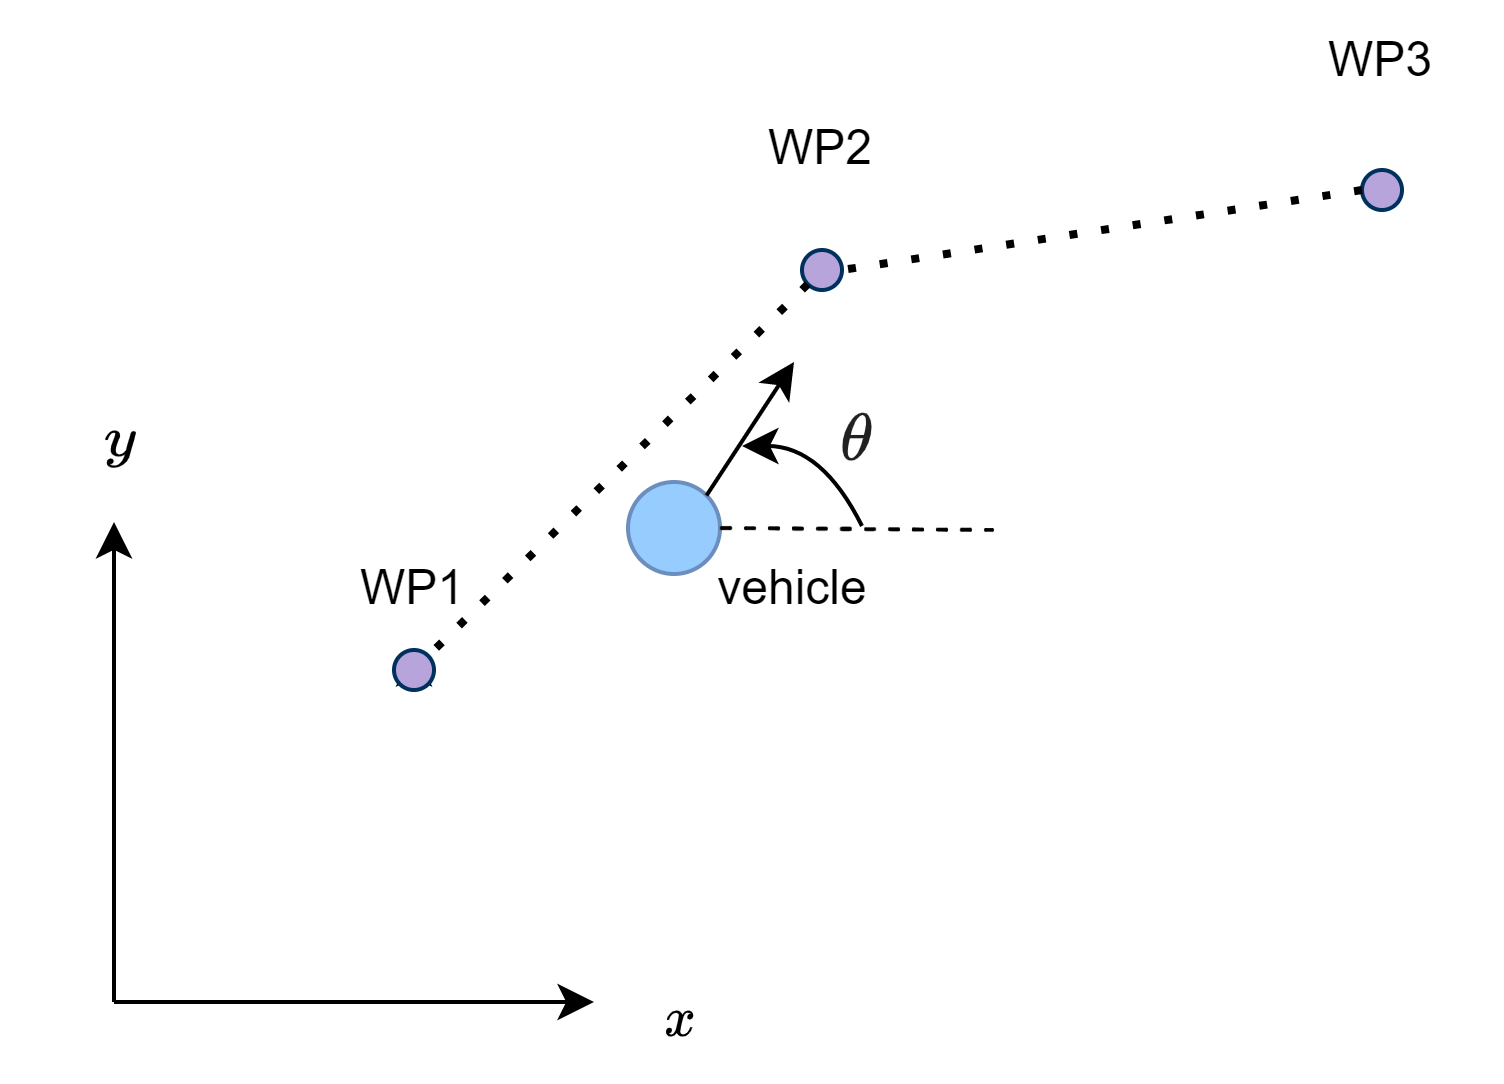

### Look Ahead Distance

To tune this algorithm, the look ahead distance $l_d$ can be adjusted. It states how far ahead on the path the vehicle should look from its current position. A small look ahead distance results in quickly moving towards the path but thus overshoots are possible. A large look ahead distance on the other hand avoids these overshoots but lets the vehicle move slower towards the path which may result in larger curvatures in corners.

### Steering Angle

The output that is used to compute the steering angle $\delta$ command for the vehicle kinematic bicycle model, is the target direction $\alpha$:

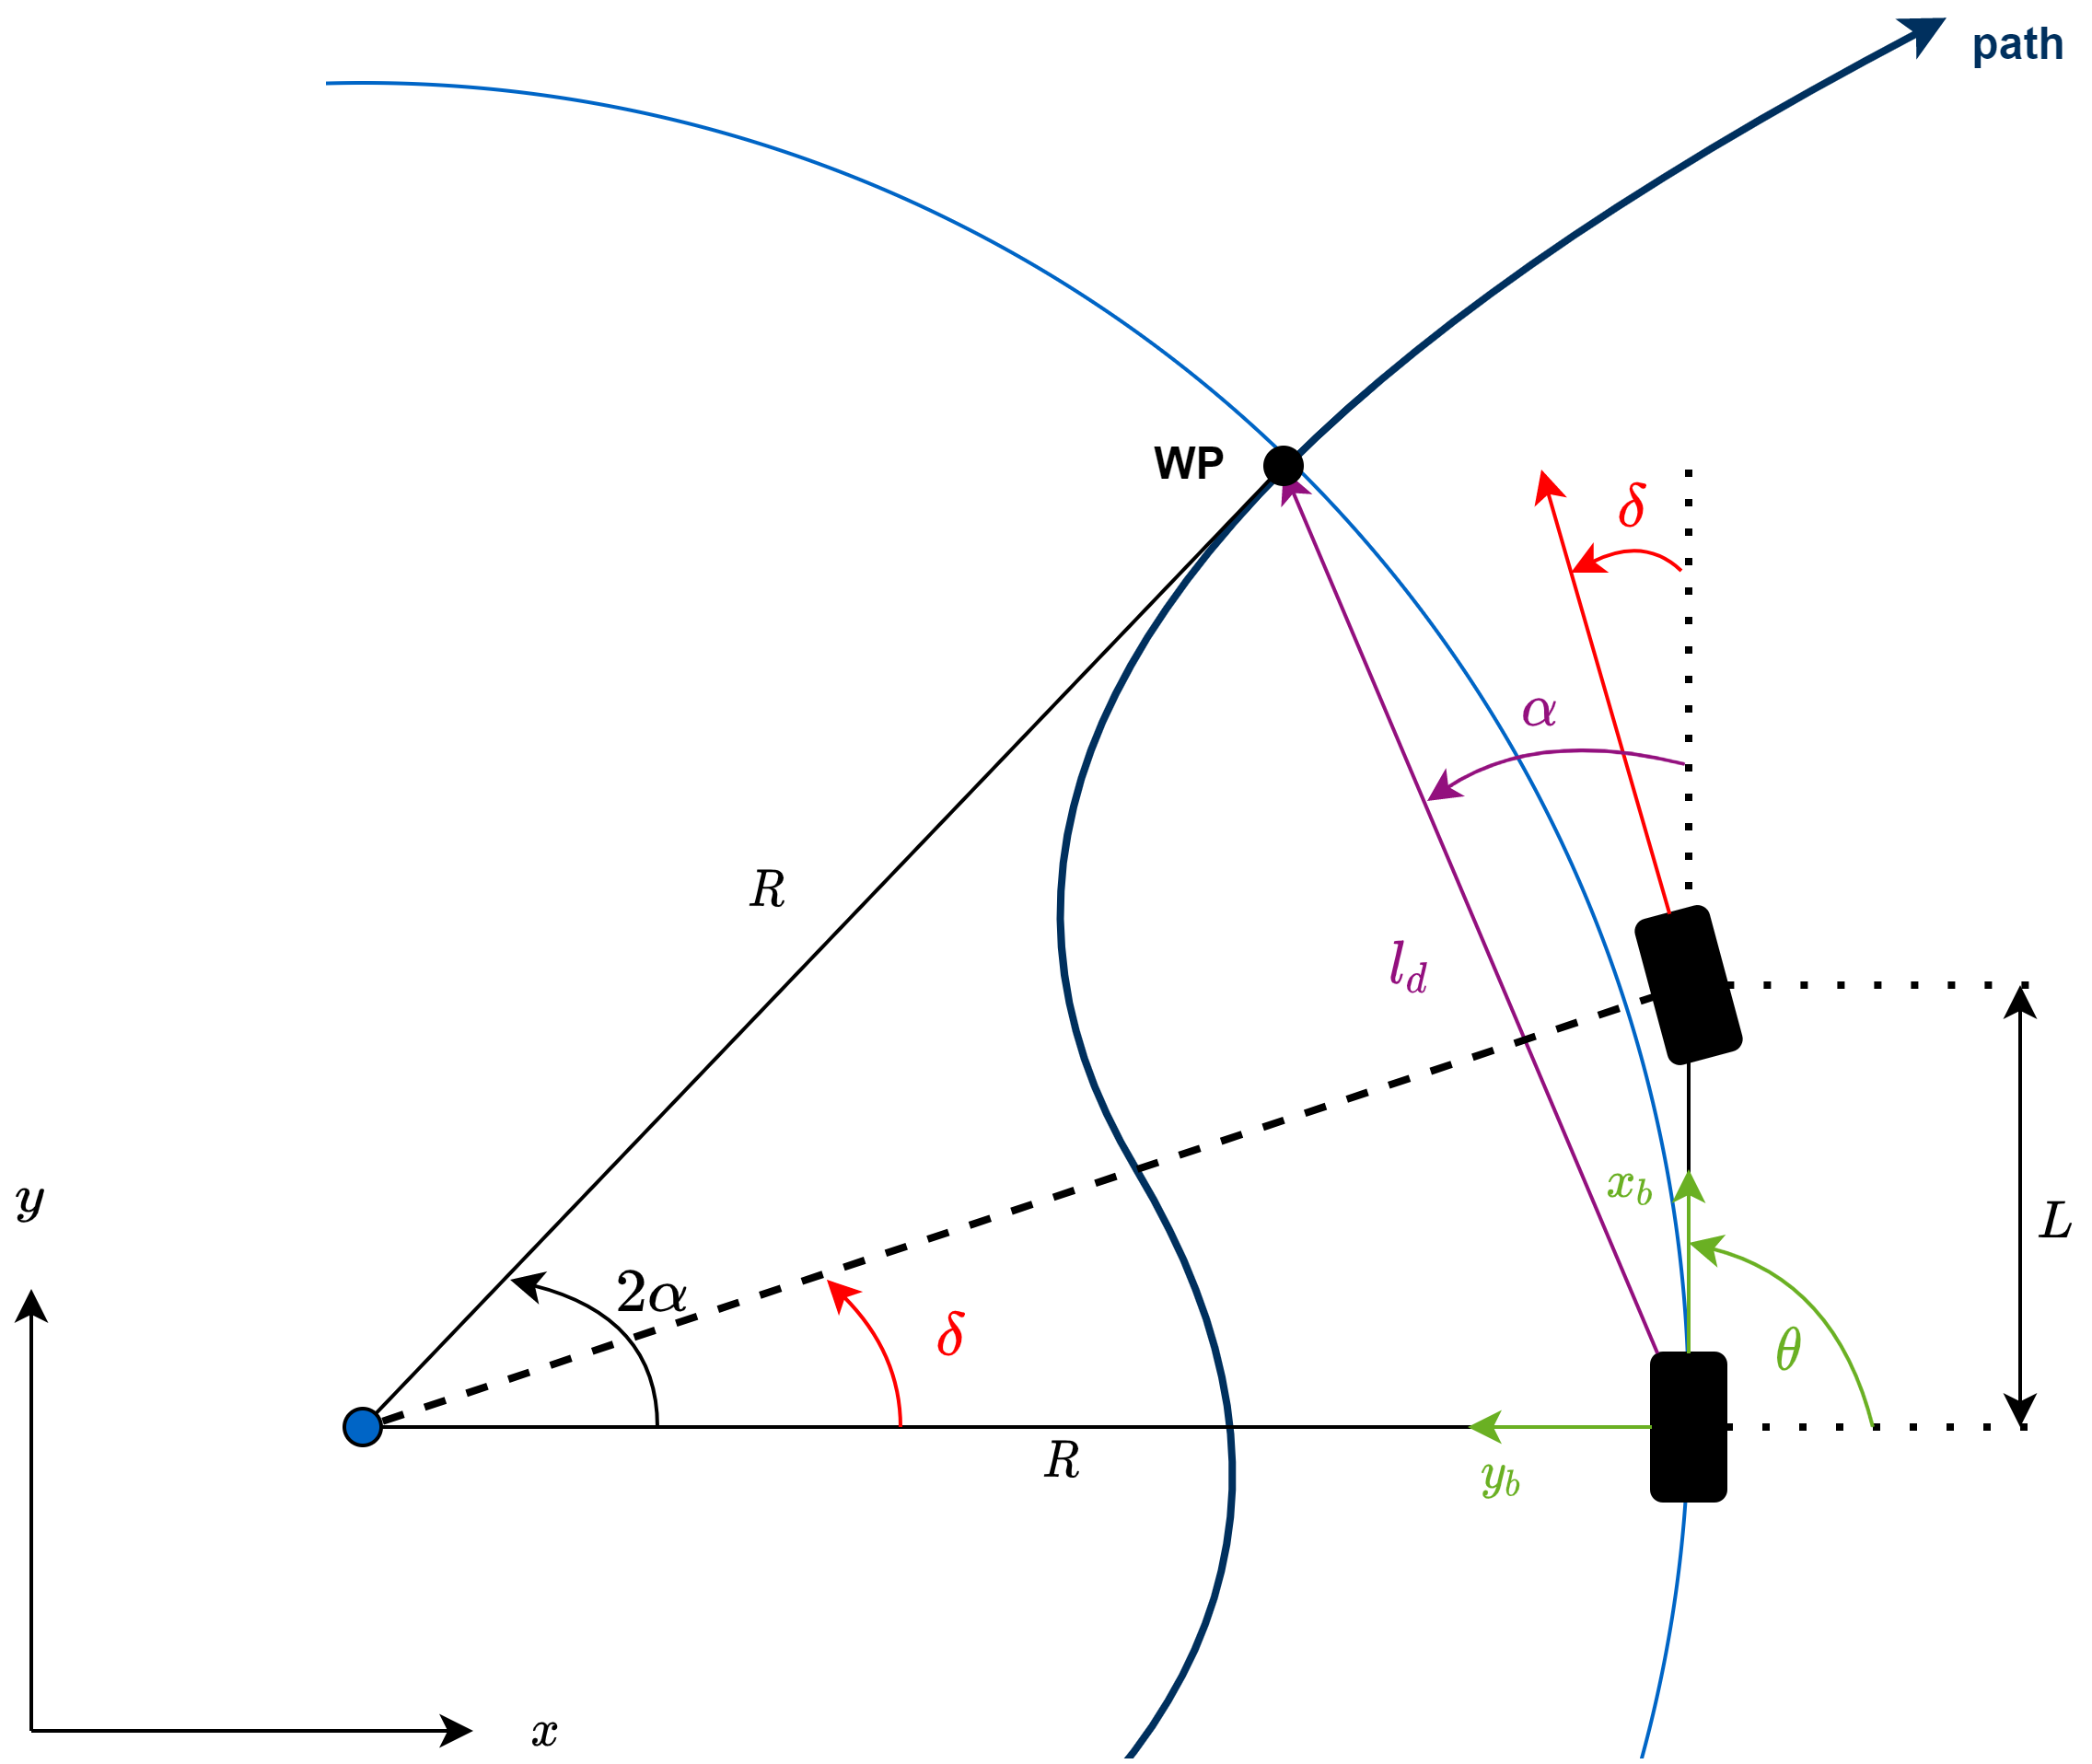

The steering angle $\delta$ can be calculated as follows:


$$\delta = arctan(\frac{L}{R})$$


From the law of sines, $R$ can be obtained:

 
$$\frac{l_d}{sin(2\alpha)} = \frac{R}{sin(\frac{\pi}{2} - \alpha)}$$



$$\frac{l_d}{2\sin(\alpha)\cos(\alpha)} = \frac{R}{cos(\alpha)}$$



$$R = \frac{l_d}{2\sin(\alpha)}$$


This results in:


$$\delta = arctan\left( \frac{2\ L\ sin(\alpha)}{l_{d}} \right)$$


### References

[https://www.mathworks.com/help/robotics/ug/pure-pursuit-controller.html](https://www.mathworks.com/help/robotics/ug/pure-pursuit-controller.html)

[https://www.youtube.com/watch?v=qYR7mmcwT2w](https://www.youtube.com/watch?v=qYR7mmcwT2w)

[https://www.youtube.com/watch?v=r_FEKkeN_fg](https://www.youtube.com/watch?v=r_FEKkeN_fg)

Coulter, R. *Implementation of the Pure Pursuit Path Tracking Algorithm*. Carnegie Mellon University, Pittsburgh, Pennsylvania, Jan 1990.

## Pure Pursuit Waypoint Generator

To provide the reference waypoints for the Pure Pursuit algorithm, the [PurePursuitWPGenerator](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner\PurePursuitWPGenerator.m')) is used:

First of all, the current pose is transformed to Frenet coordinates. Then, at every time step, the trajectory will be planned (planReferenceTrajectory) for the specified time horizon. Finally the next waypoints in the trajectory ([getNextFrenetTrajectoryWaypoints](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('getNextFrenetTrajectoryWaypoints'));)) will be transformed back to Cartesian coordinates to provide the input for the Pure Pursuit algorithm.

## Lateral Stanley Controller

The Lateral Stanley Controller can also be used for path tracking. Using the kinematic bicycle model, the inputs are:

- The reference pose $[x_{ref}, y_{ref}, \theta _{ref}]$: While only considering forward motion, the reference location $[x_{ref}, y_{ref}$ is the point on the path which is closest to the center of the vehicle's front axle. The reference angle $\theta _{ref}$ is the orientation at this reference location on the path.

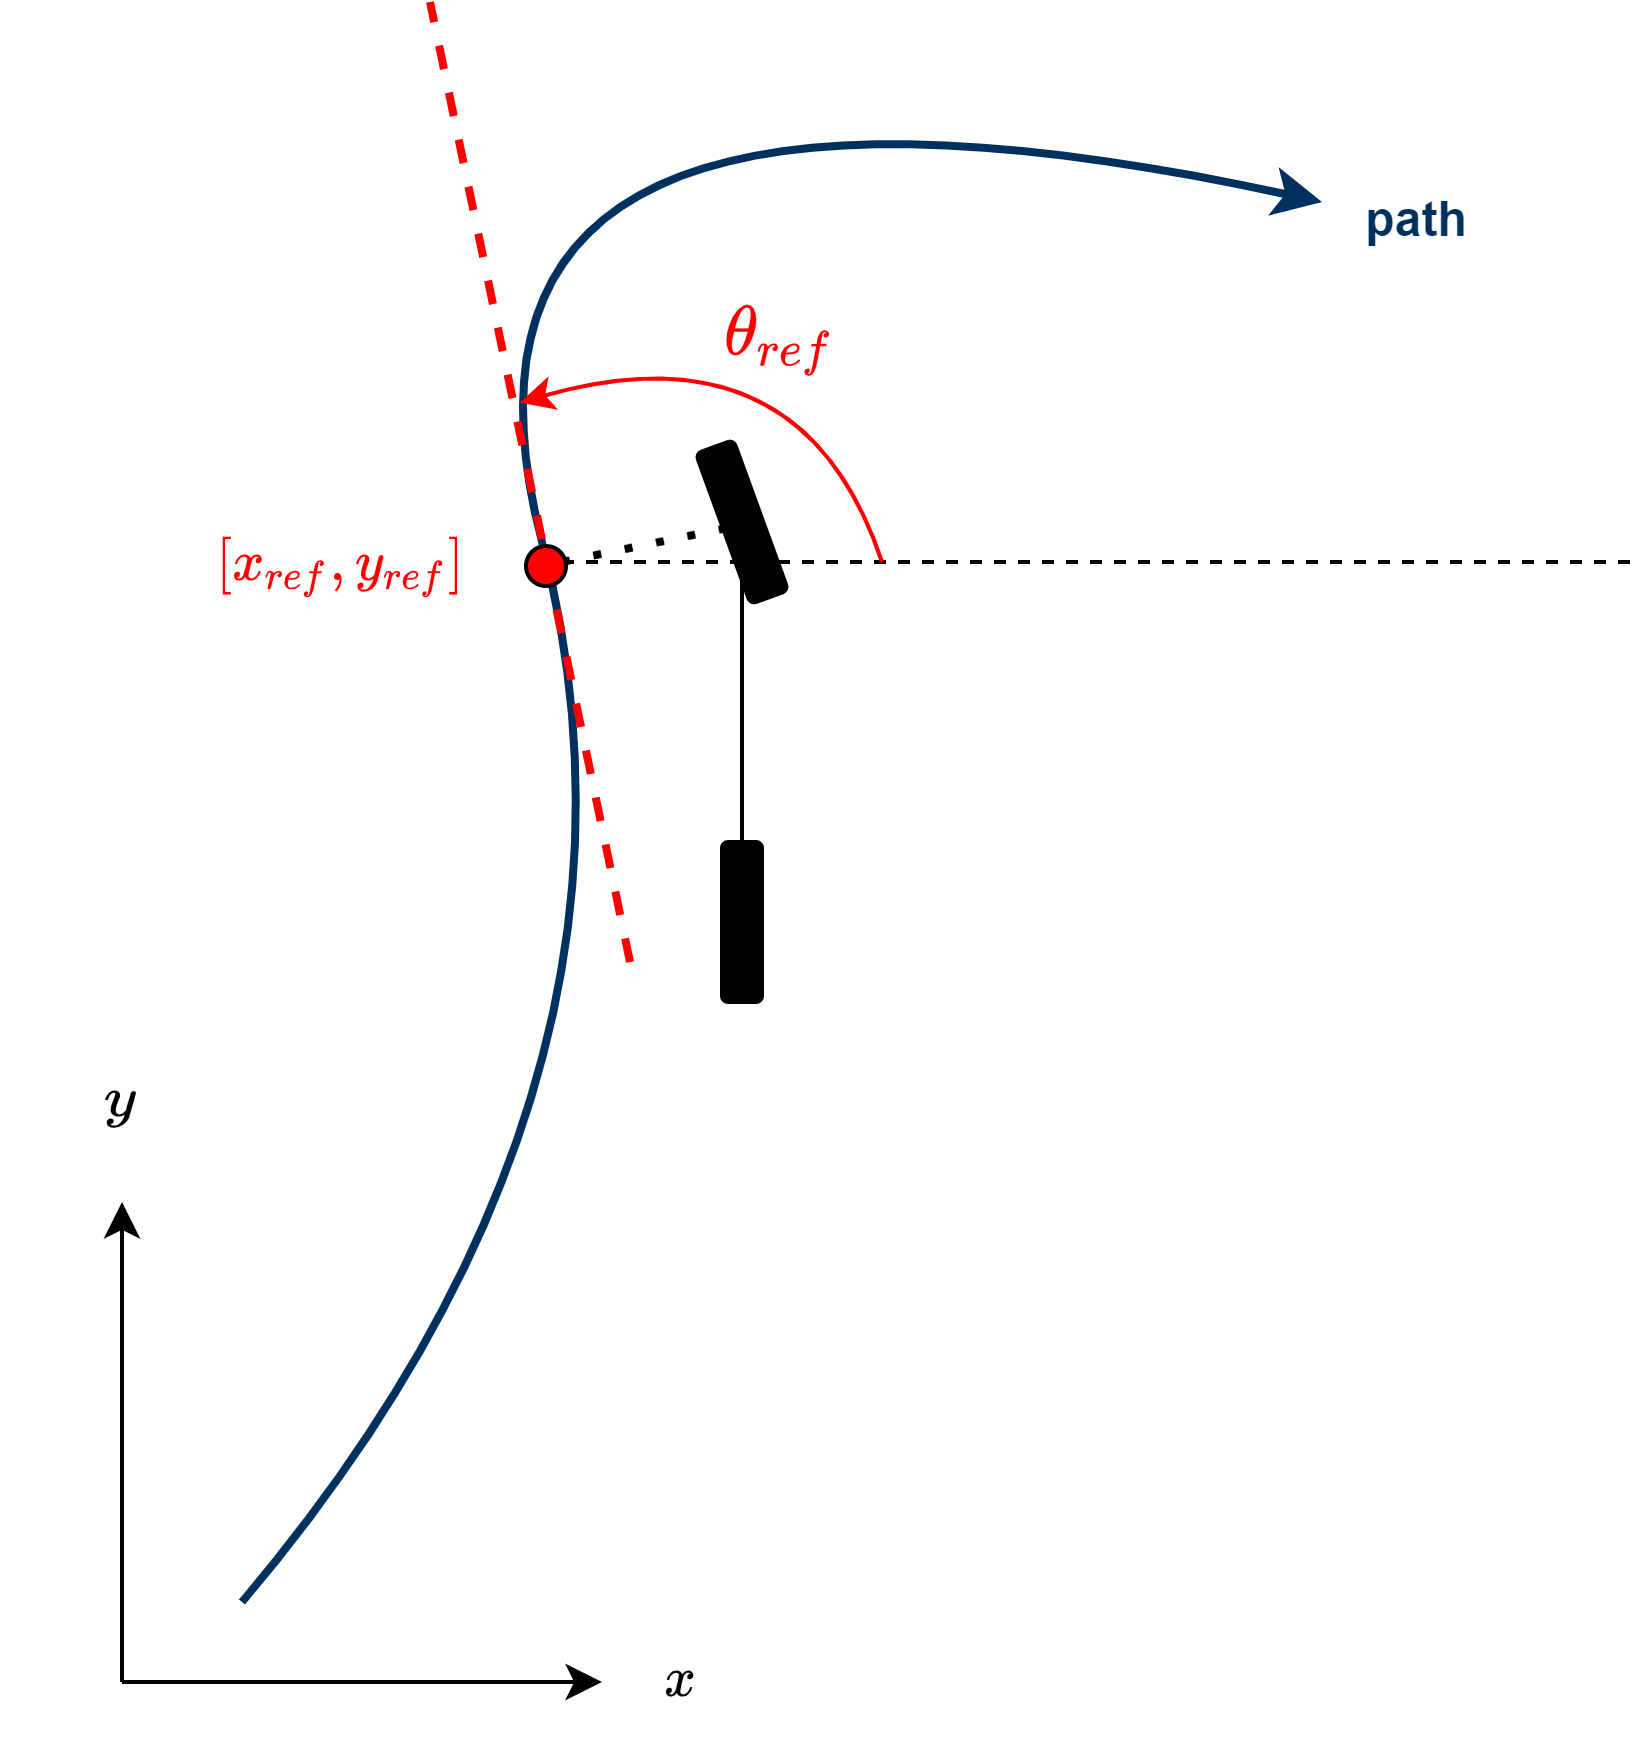

- The current pose $[x, y, \theta ]$: This is the current pose of the vehicle according to the center of the vehicle's rear axle.

- The current velocity of the vehicle

- The vehicle's direction: The constant 1 is used for forward motion.

The controller outputs the steering angle $\delta$ in degrees. Therefore, to use this angle as the input for the bicycle kinematic model, a transformation to radians is necessary.

### Position Gain Of Forward Motion

To tune the controller, the position gain can be adjusted. For forward motion, only the position gain for forward motion needs to be considered. The higher this value is, the more the position error will affect steering angle adjustmens.

### Steering Control Law

The steering control law considers the cross track error $e(t)$, the vehicles speed $v(t)$ and the vehicle's heading $\psi (t)$ with respect to the closest trajectory segment (see figure below). The reference point is the center of the vehicle's front axle. For the kinematic bicycle model, the steering angle $\delta(t)$ is calculated as follows, with $k$ being the gain and $\delta_{max}$ being the maximum steering angle:


$$\delta(t) =
    \begin{cases}
      \psi(t) + arctan(\frac{k\ e(t)}{v(t)}) & \text{if } |\psi(t) + arctan(\frac{k\ e(t)}{v(t)})| < \delta_{max} \\
      \delta_{max} & \text{if }  \psi(t) + arctan(\frac{k\ e(t)}{v(t)}) \geq \delta_{max} \\
      -\delta_{max}  &  \text{if } \psi(t) + arctan(\frac{k\ e(t)}{v(t)}) \leq \delta_{max} \\
    \end{cases} $$


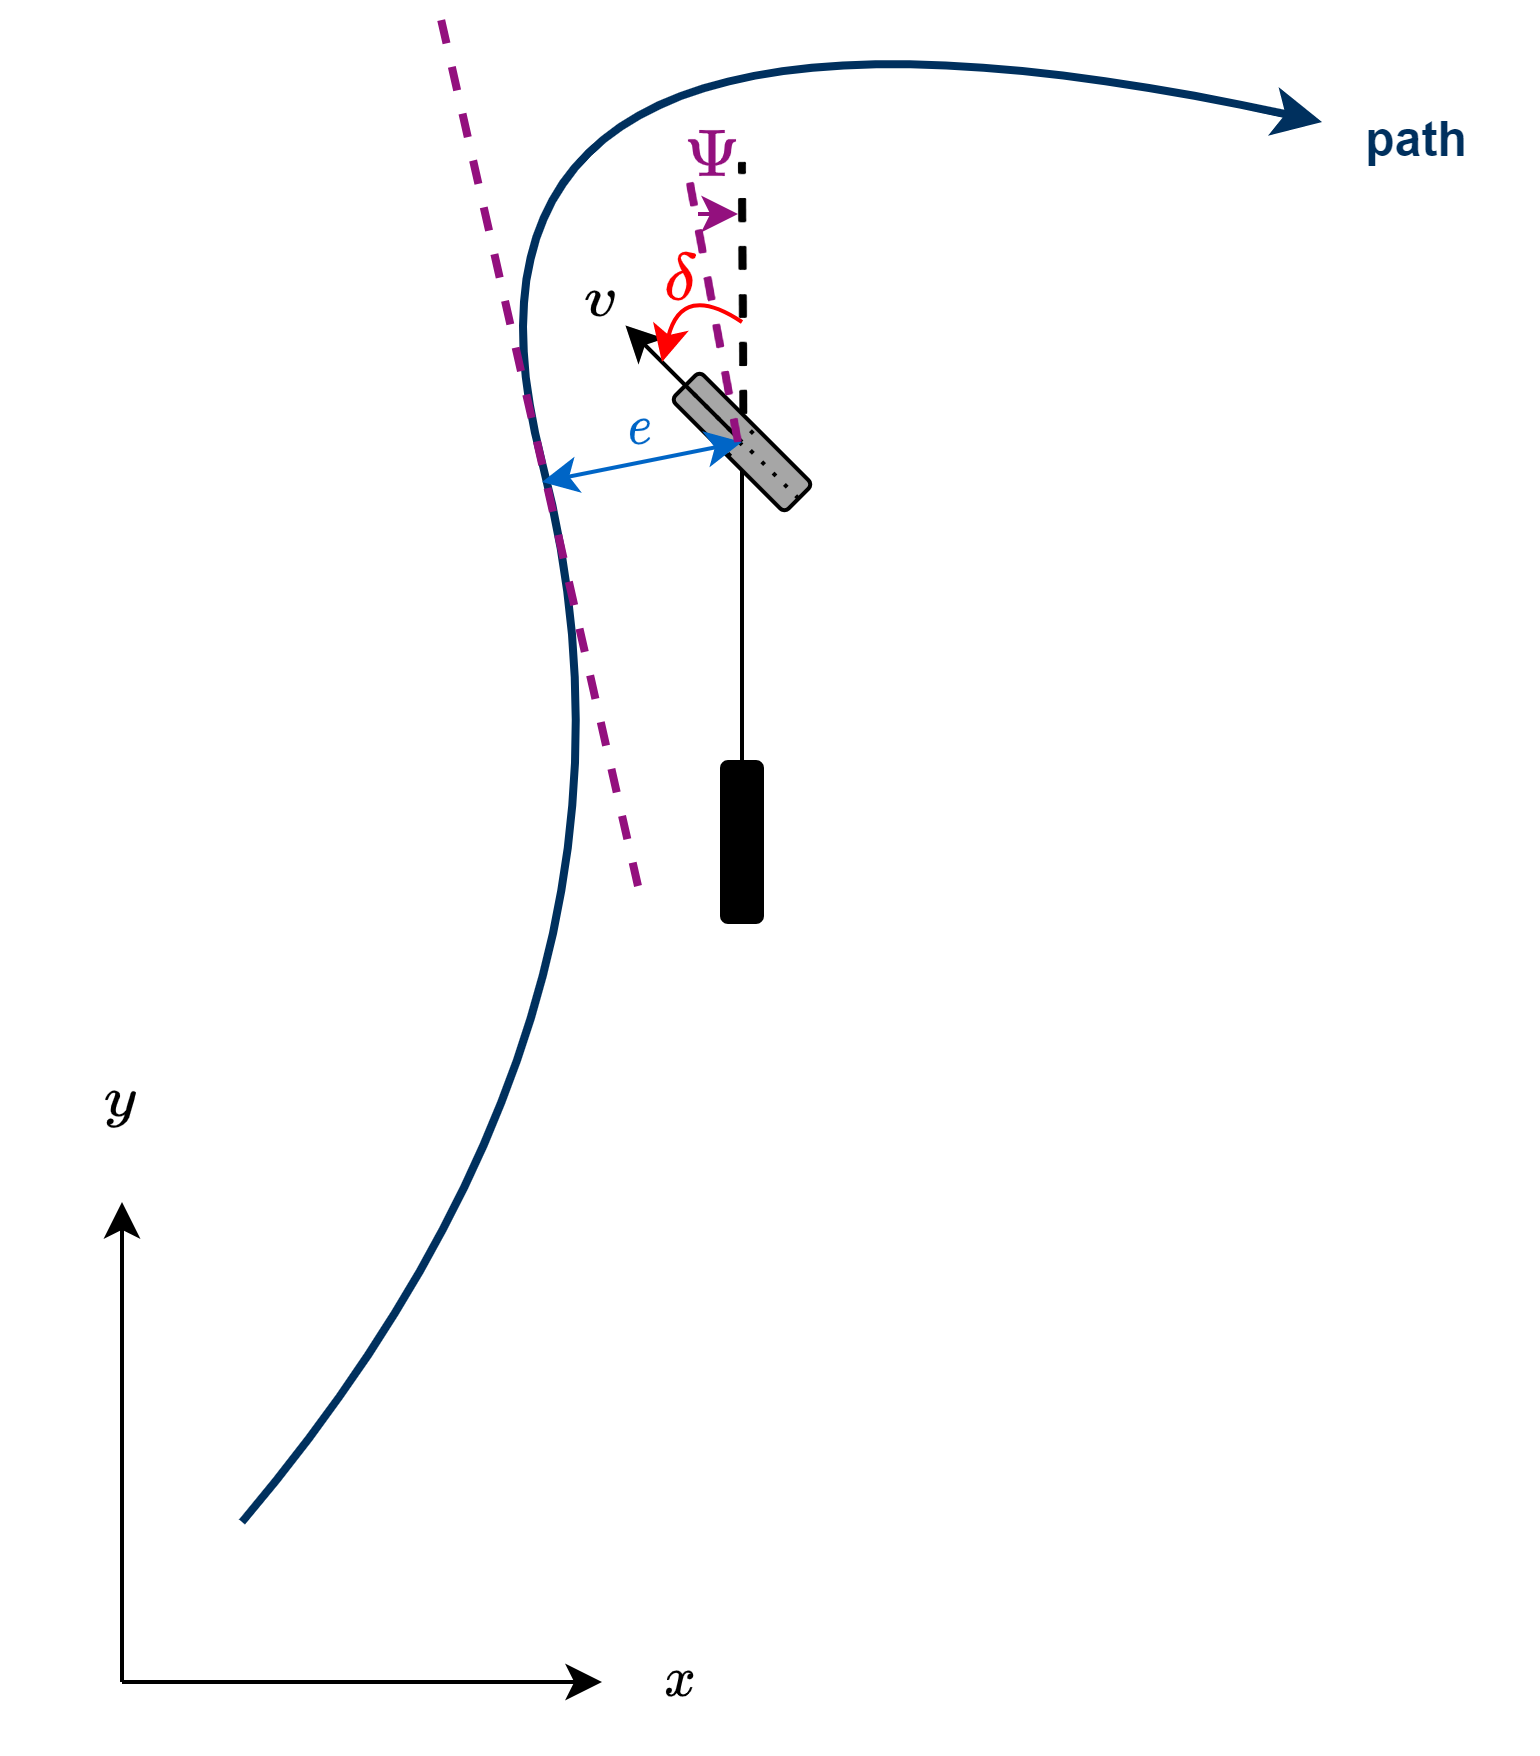

### Stability


$$e = 0  \ \text{for} \ v(t) > 0 \ \text{and} \ 0 < \delta_{max} < \frac{\pi}{2} 
$$


### 
$$\dot e(t) = v(t)sin(\psi(t) - \delta(t))
= \frac{-ke(t)}{\sqrt{1 + (\frac{ke(t)}{v(t)})^2}}
\approx -ke(t)$$


### Error Minimisation

To reduce the cross track error $e = d_{actual} - d_{reference}}$ for tracking the desired path, the [Global Optimization Toolbox](https://www.mathworks.com/products/global-optimization.html) with a [Genetic Algorithm](https://www.mathworks.com/discovery/genetic-algorithm.html) is used. Therefore the functions [error_d_optimisation](matlab:open('./ParamOptimiser\error_d_optimisation.m')) and [error_d](matlab:open('./ParamOptimiser\error_d.m')) are created, to find the optimal value for the position gain of forward motion.

### References

[https://www.mathworks.com/help/driving/ref/lateralcontrollerstanley.html](https://www.mathworks.com/help/driving/ref/lateralcontrollerstanley.html)

[https://www.youtube.com/watch?v=9Y7kVIJs_JI](https://www.youtube.com/watch?v=9Y7kVIJs_JI)

Hoffmann, Gabriel M., Claire J. Tomlin, Michael Montemerlo, and Sebastian Thrun. "Autonomous Automobile Trajectory Tracking for Off-Road Driving: Controller Design, Experimental Validation and Racing." *American Control Conference*. 2007, pp. 2296–2301. doi:10.1109/ACC.2007.4282788

## Stanley Pose Generator

To provide the reference pose for the Stanley controller, the [StanleyPoseGenerator](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner\StanleyPoseGenerator.m')) is used:

First of all, the current pose is transformed to Frenet coordinates. Then, at every time step, the trajectory will be planned (planReferenceTrajectory) for the specified time horizon. A reference pose according to the center of the ego vehicle's front axle ([getVehicleFrontAxleCenterPoint](matlab:open('./Vehicle Functions\Helper Functions\getVehicleFrontAxleCenterPoint.m'))) must be generated ([getReferencePoseStanley](matlab:matlab.desktop.editor.openAndGoToLine(which('StanleyPoseGenerator.m'),  getFunctionLineNr('getReferencePoseStanley'));)):

It is necessary to find the waypoint on the reference trajectory which is closest to the center of the vehicle's front axle. In case of a lane change, the reference trajectory is the trajectory calculated at the start of the lane changing maneuver. When the vehicle is following a lane, a specific reference trajectory does not have to be generated because it is already given by the road geometry (*obj.RoadTrajectory*). Thus, it is only necessary to get the next $s$-value by projecting the center of the front axle on the road trajectory which is done by the  Cartesian2Frenet-transformation. . The reference orientation for a lane change was already generated, when planning the trajectory. For a straight trajectory, the reference orientation is equal to the road orientation at the determined reference position.

# Longitudinal Reachability Analysis


$$x(t) = x_0 + vt + \frac{1}{2}at^2 \\
v(t) = v_0 + at$$



$$$\left[ \begin{array}{r}
x(k+1) \\ 
v(k+1)\\
\end{array}\right]$

=

$\left[ \begin{array}{rr}
1 & T_{s}  \\ 
0 & 1  \\
\end{array}\right]$

$\left[ \begin{array}{r}
x(k) \\ 
v(k) \\ 
\end{array}\right]$

+

$\left[ \begin{array}{r}
\frac{T_{s}^2}{2} \\
T_{s} \\
\end{array}\right ] a(k)$

$$


For the leading vehicle a longitudinal reachability analysis is done to estimate its future position $s$ and velocity $v$ when applying the maximum or minimum possible longitudinal acceleration $a_{max}$ or $a_{min}$ for a specified time horizon. The future states at time step $k+1$ can be calculated by the following expression with $T_{s}$ being the sample time:


$$$\left[ \begin{array}{r}
x(k+1) \\ 
v(k+1)\\
\end{array}\right]$

=

$\left[ \begin{array}{rr}
1 & (k+1)T_{s}  \\ 
0 & 1  \\
\end{array}\right]$

$\left[ \begin{array}{r}
x(0) \\ 
v(0) \\ 
\end{array}\right]$

+

$\left[ \begin{array}{r}
\frac{T_{s}^2}{2}  \sum\nolimits_{j=0}^k\ (2k + 1 - 2j)a_{j} \\
T_{s} \sum\nolimits_{j=0}^k\ a_{j} \\
\end{array}\right]$$$


With the maximum or minimum acceleration being constant, this simplifies to:


$$$\left[ \begin{array}{r}
x(k+1) \\ 
v(k+1)\\
\end{array}\right]$

=

$\left[ \begin{array}{rr}
1 & (k+1)T_{s}  \\ 
0 & 1  \\
\end{array}\right]$

$\left[ \begin{array}{r}
x(0) \\ 
v(0) \\ 
\end{array}\right]$

+

$\left[ \begin{array}{r}
\frac{T_{s}^2}{2} \ a \sum\nolimits_{j=0}^k\ (2j + 1) \\
 \ T_{s}  (k + 1)   a   \\
\end{array}\right]$$$


# Lateral Reachability Analysis

By using the longitudinal reachability analysis with a constant acceleration $a$, the longitudinal distance $\Delta x = x(k+1) - x(0)$, which is covered in a specified time horizon $T_{h} = (k+1)T_{s}$, can be calculated. When assuming that the wheels roll without slipping sideways, $\Delta x
$ should be equal to the arc length for different constant steering angles $\delta \in [-\delta_{max}, \ \delta_{max}]$. Thus, an area limiting the possible future positions for the [ReachabilityAnalysis](matlab:open('./Vehicle Functions\ReachabilityAnalysis\ReachabilityAnalysis.m')) can be predicted:

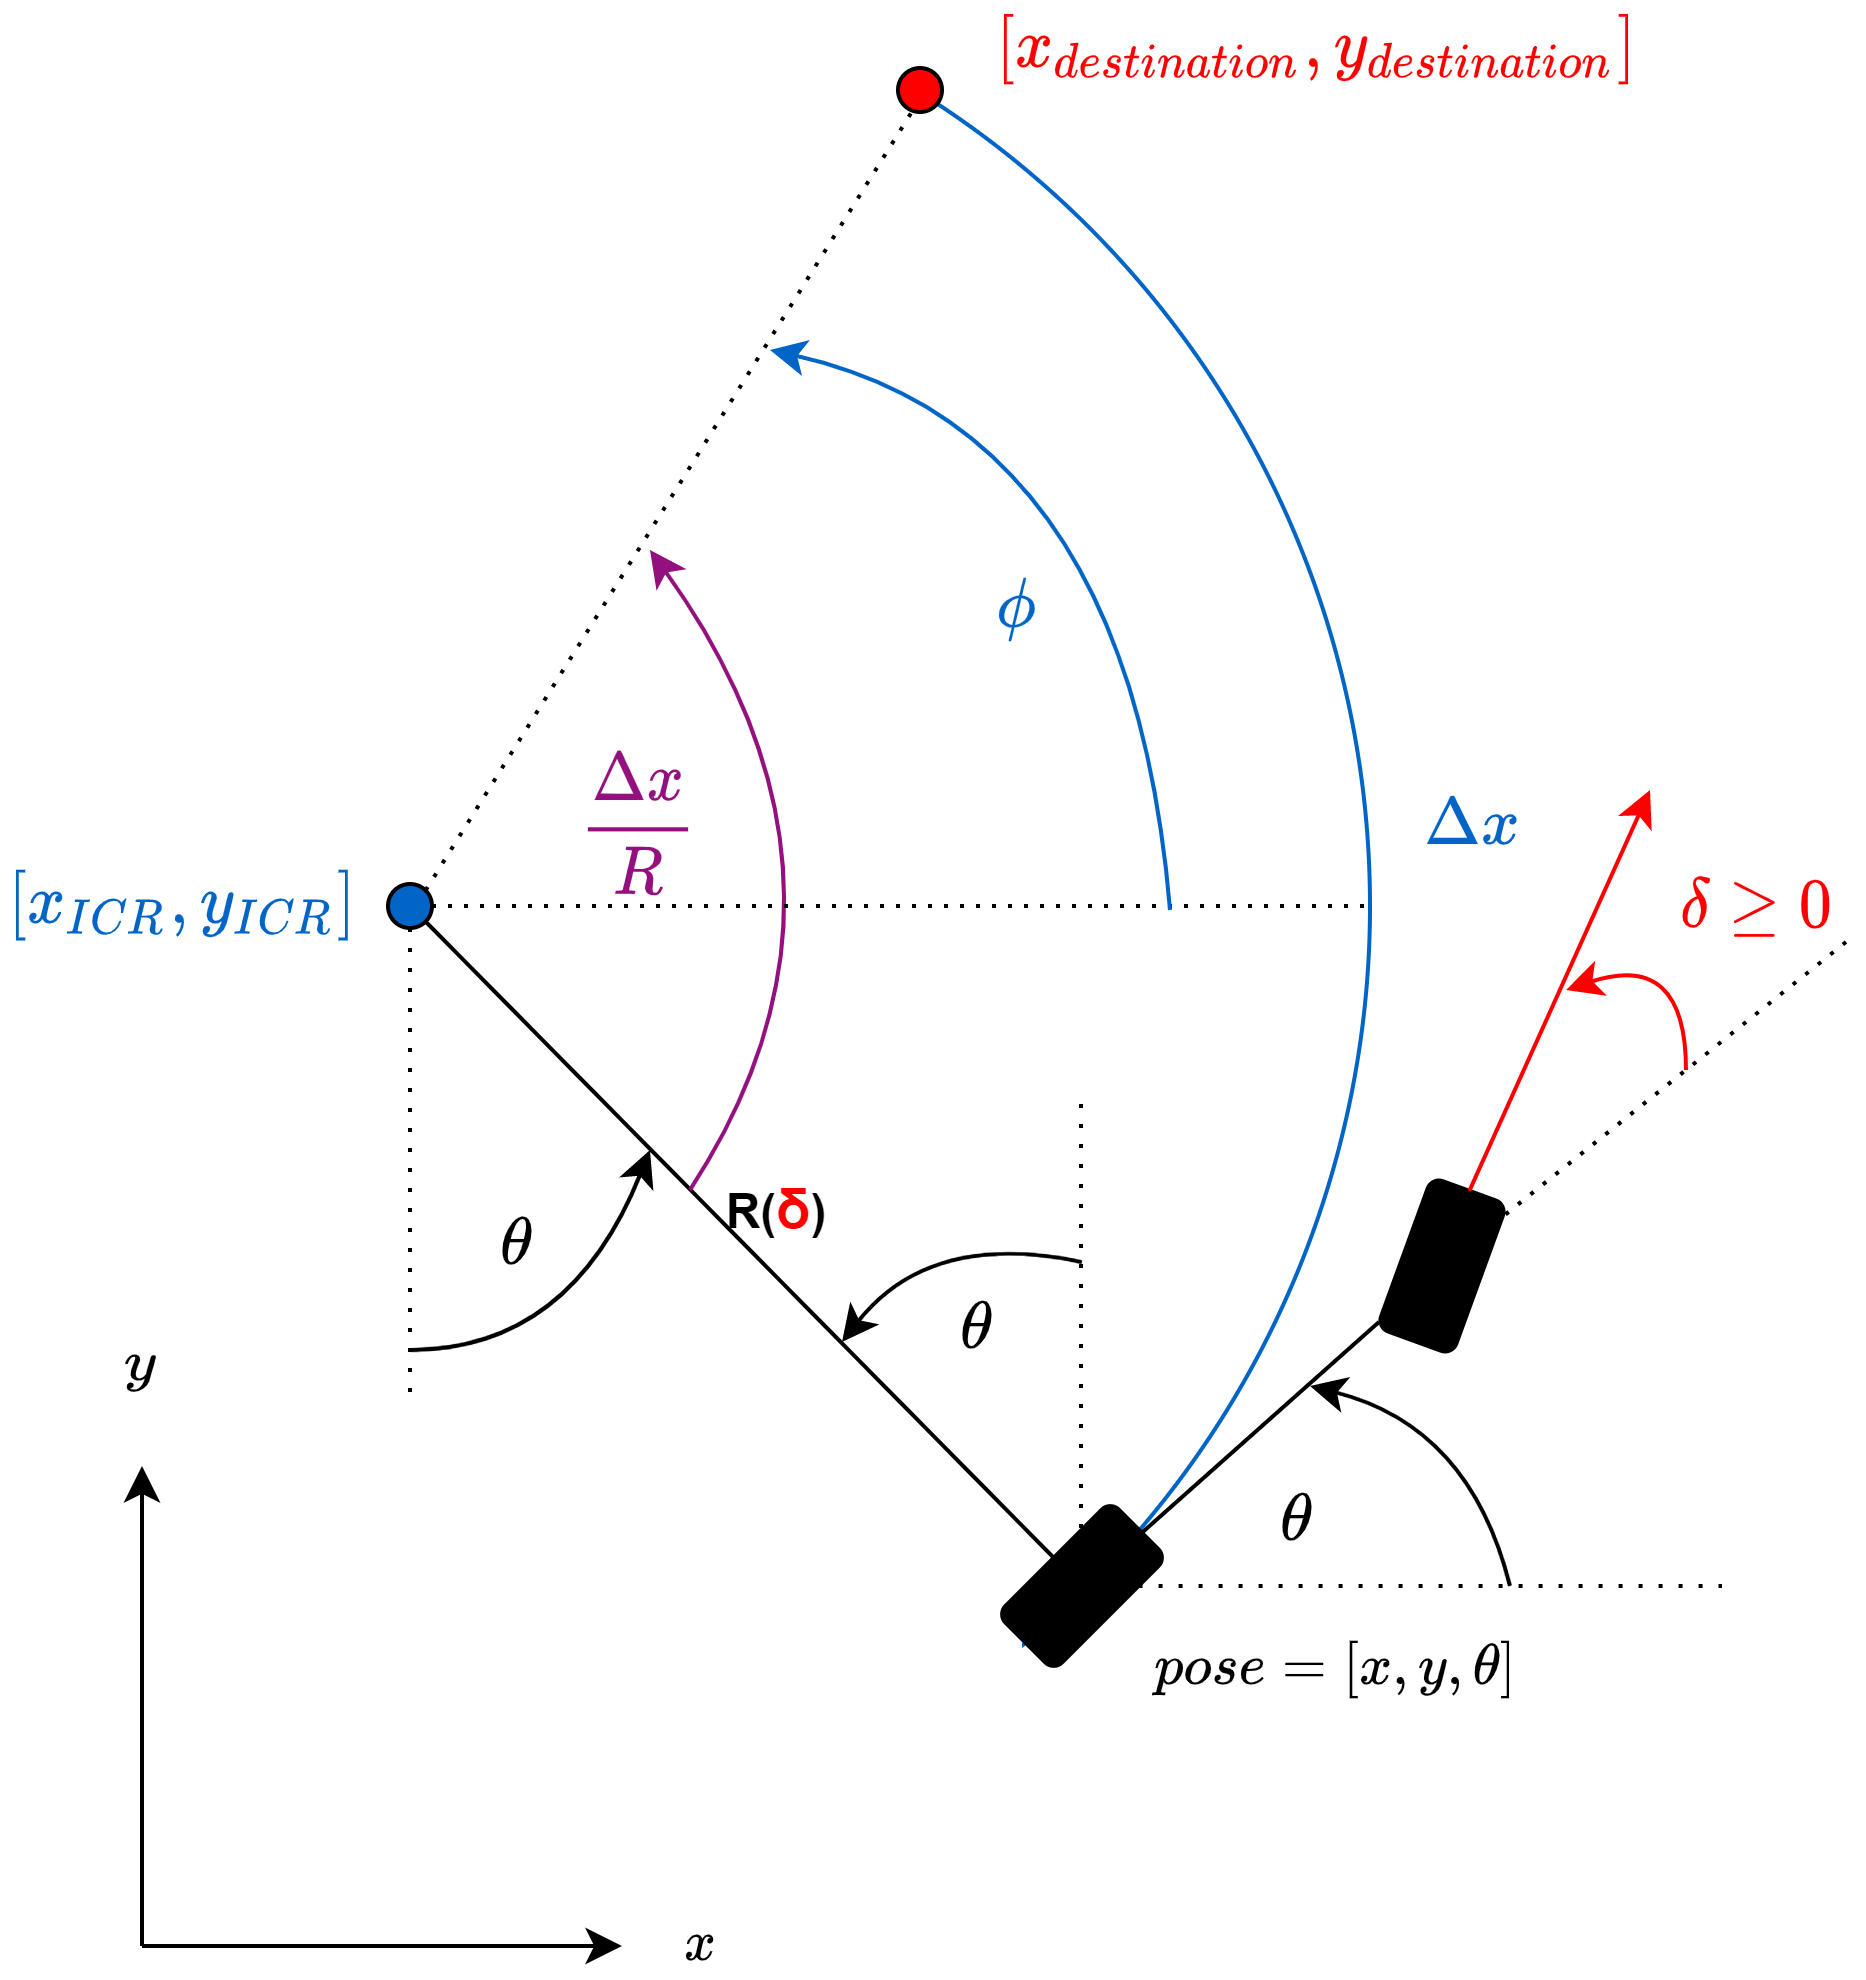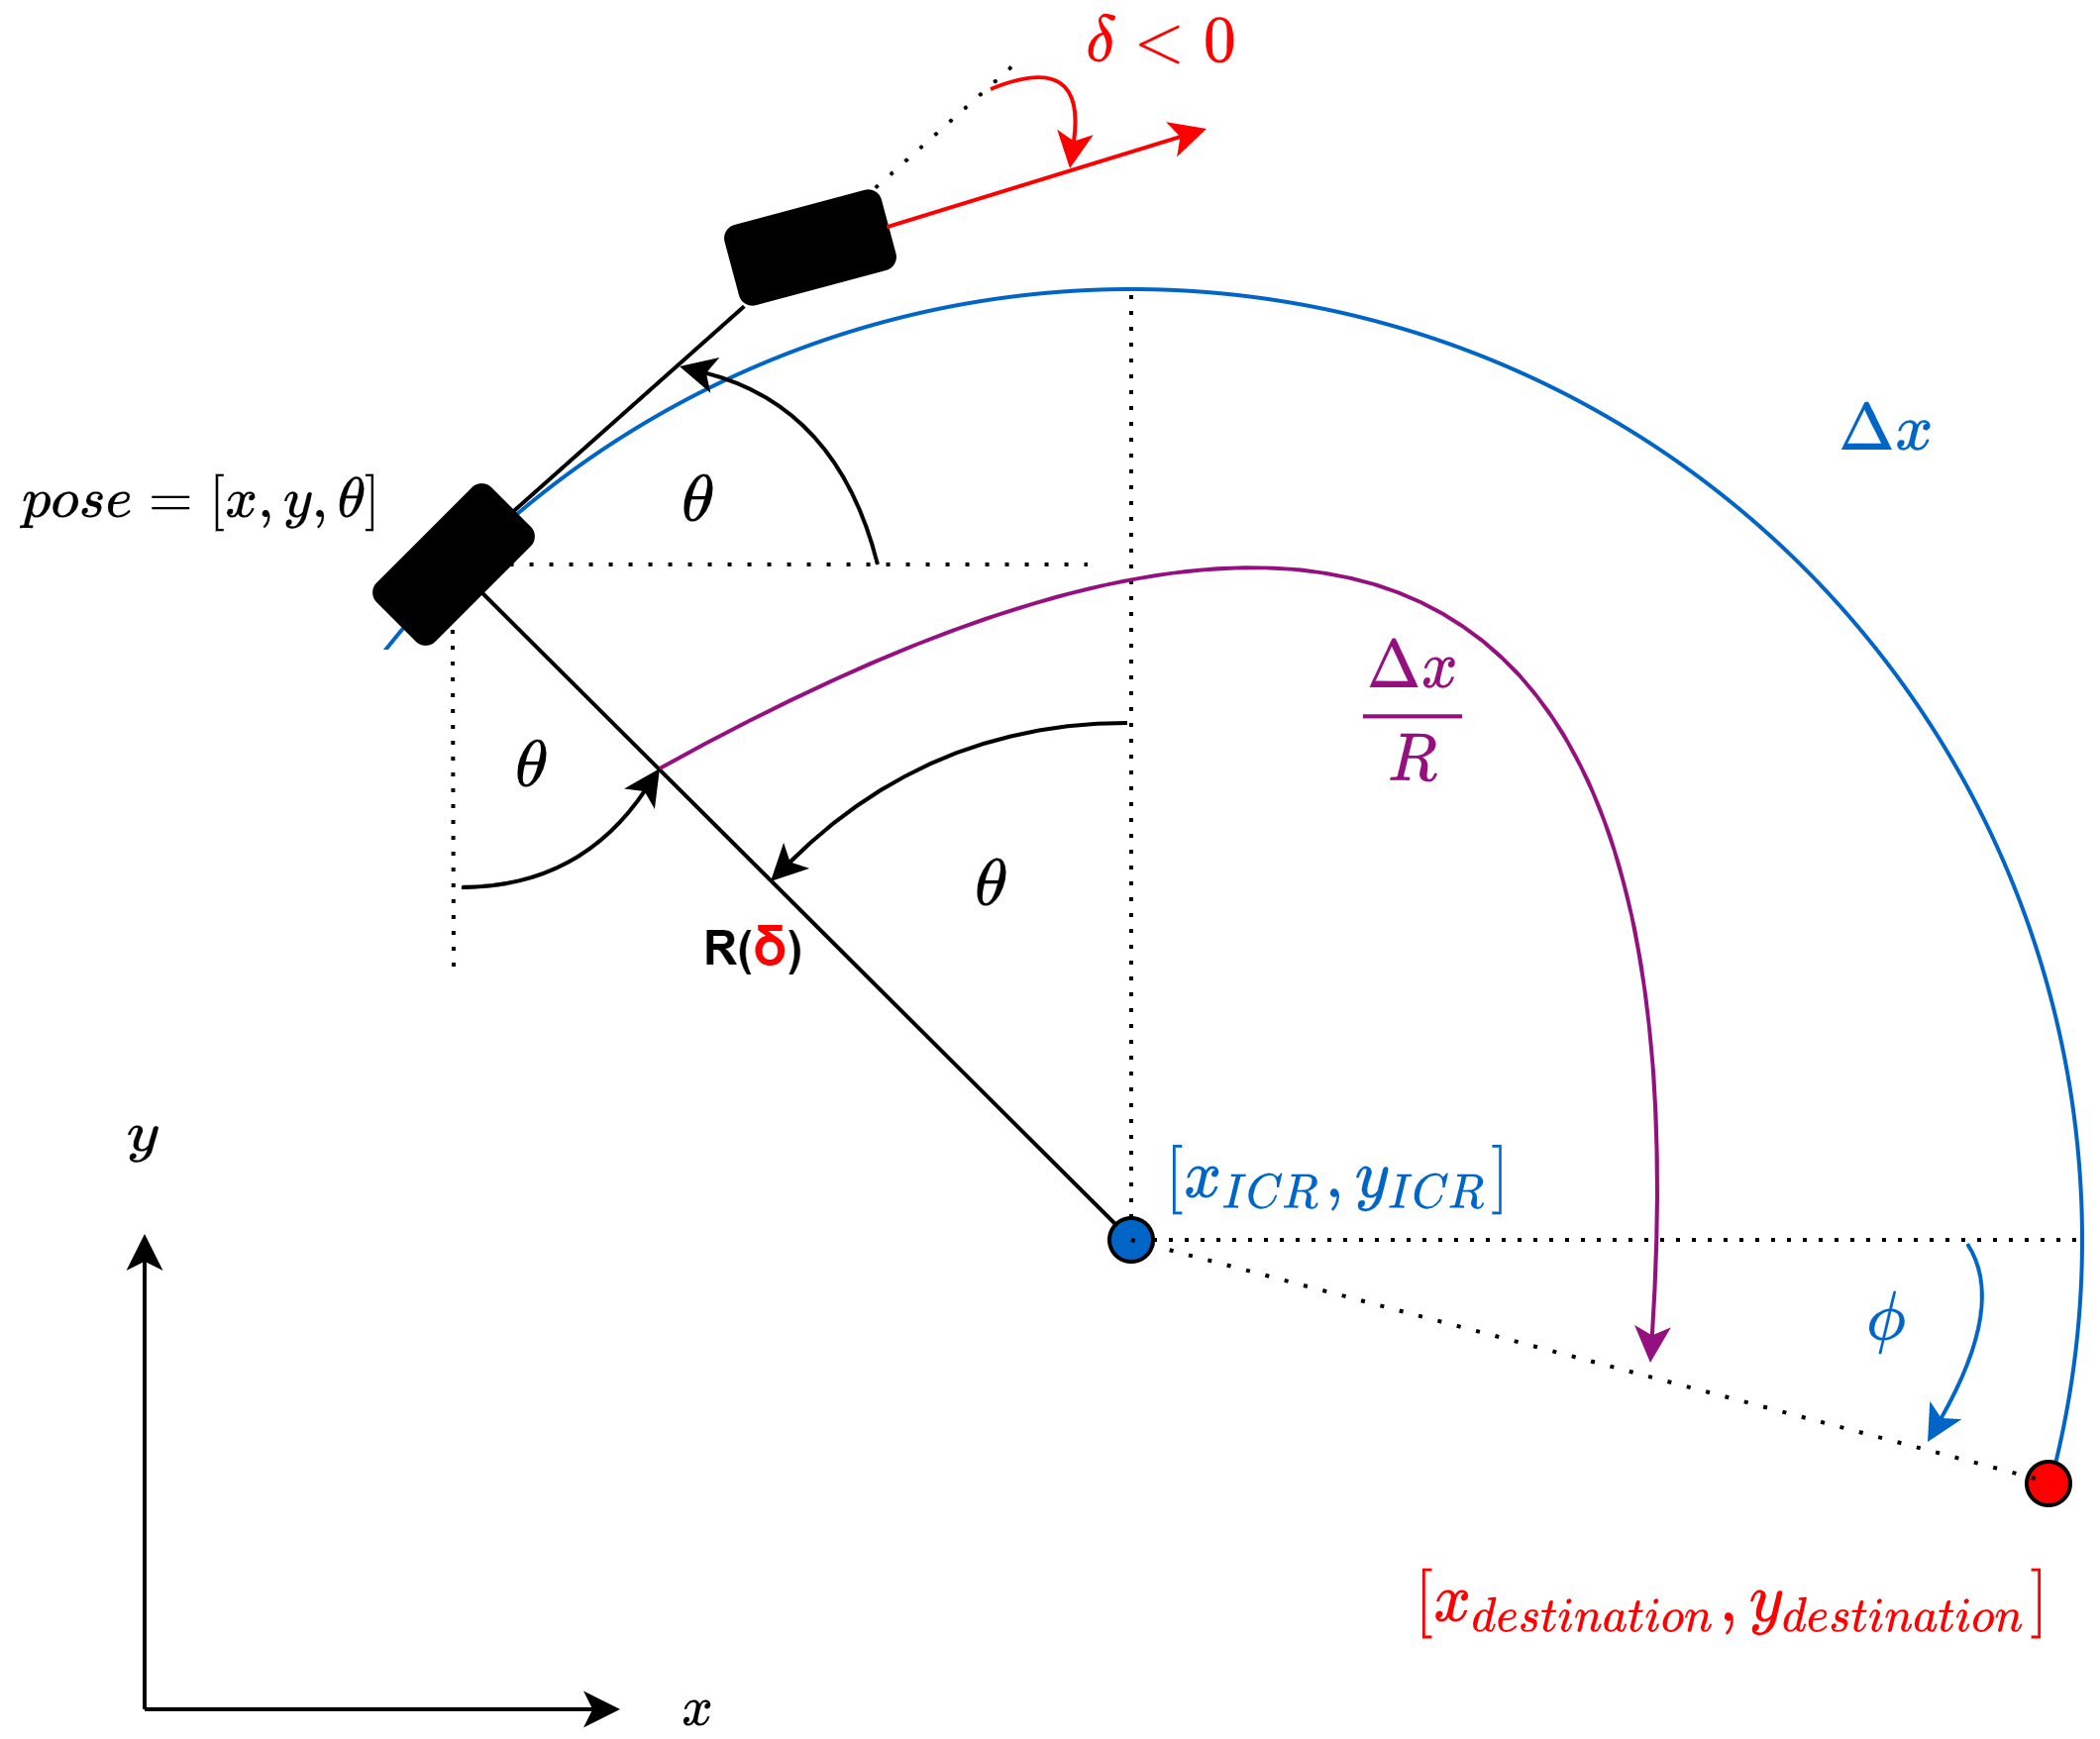

A case analysis for $\delta \geq 0$ and for $\delta < 0$ is necessary. Therefor the variable $\beta$ is defined:


$$\beta =
    \begin{cases}
      1& \text{if } \delta \geq 0 \\
      -1 & \text{if }  \delta < 0 \\
    \end{cases} $$


According to the kinematic bicycle model the turning radius is:


$$R = \beta \frac{L}{tan(\delta)} $$


The destination point $[x_{destination}, \ y_{destination}]$ after following an arc defined by the turning radius $R$ can be determined by using the arc's center point$[x_{ICR}, \ y_{ICR}]$:

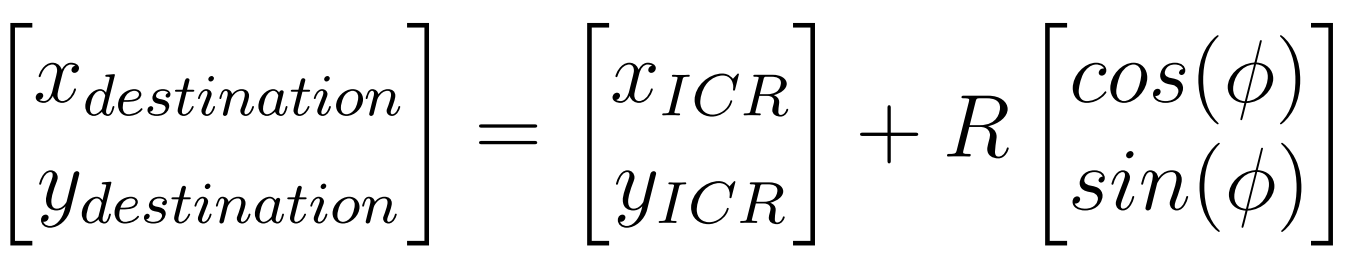

$[x_{ICR}, \ y_{ICR}]$ can be expressed using the vehicle's pose $[X, \ Y, \ \theta]$:

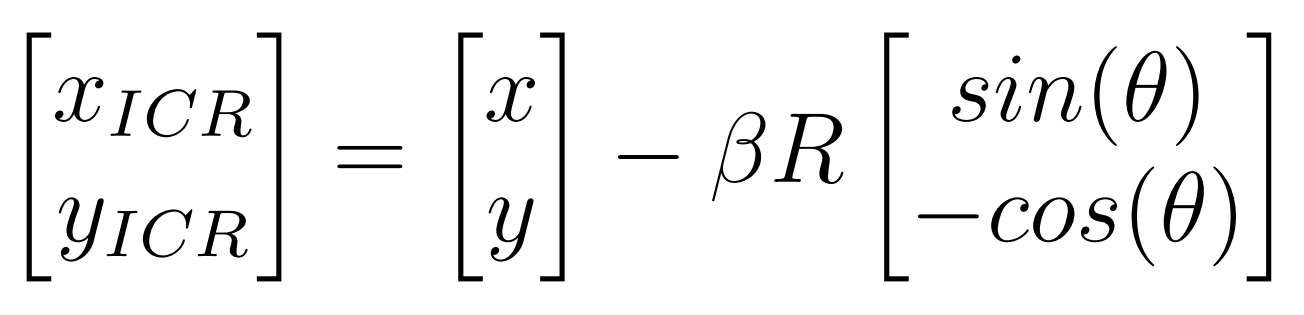

Further, $\phi$ can be determined:

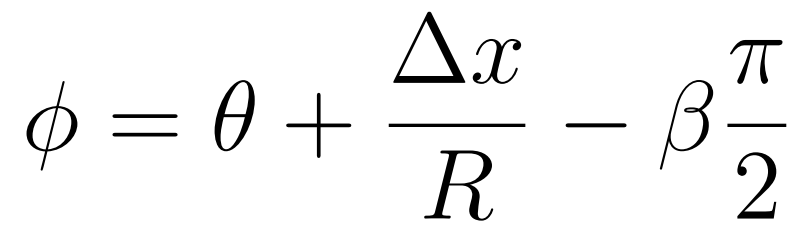

$[x_{destination}, \ y_{destination}]$ can finally be written as:

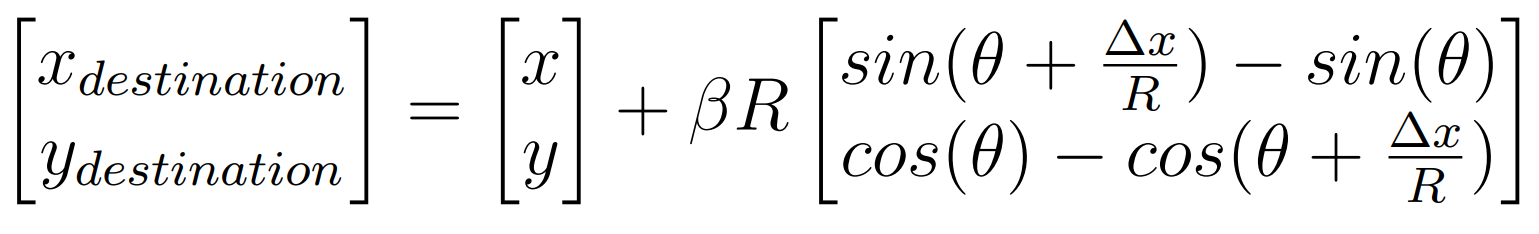

Using this formula, the boundries of the reachability area can be determined. For the lower, upper and emergency boundary, the steering angle is varied and the arc length $\Delta s$ is kept constant. For the right and left boundary, it is the other way around:

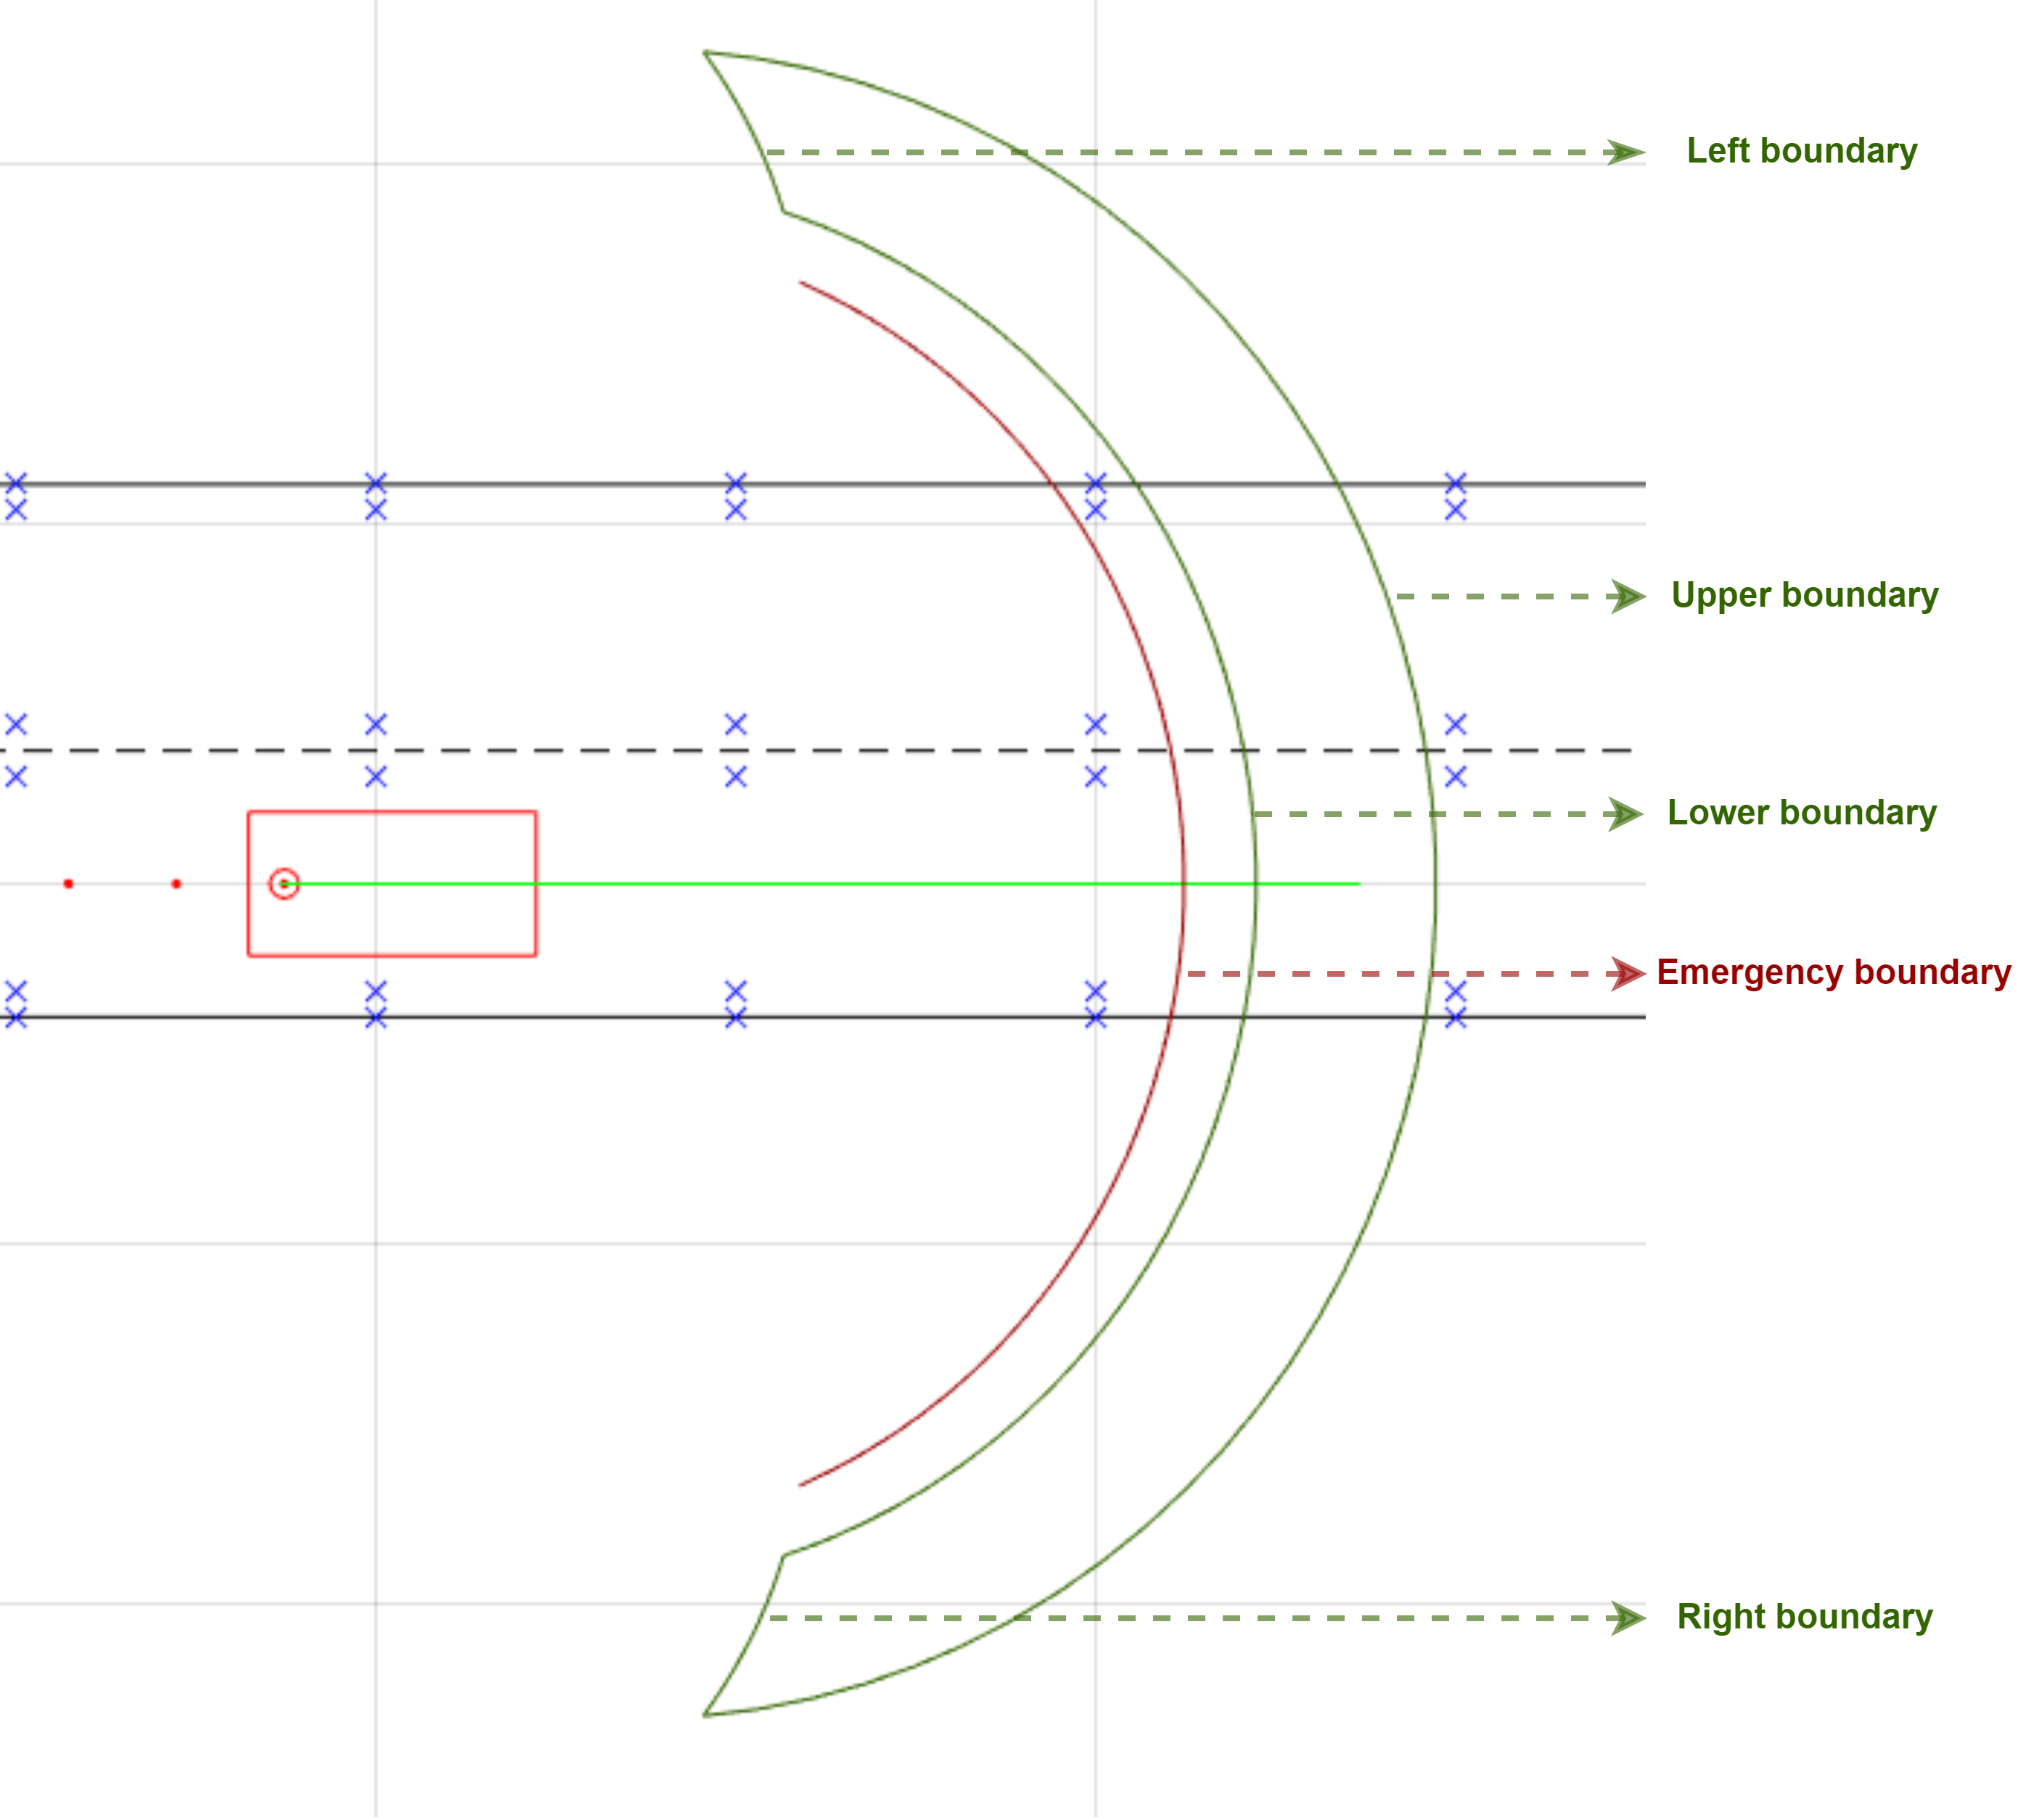


$$\begin{array}{lccc}
\text{Lower boundary} &:& a = a_{min} =  const. &,&\  -\delta_{max} \leq \delta  \leq \delta_{max}&,& \ \Delta x = x_{a_{min}}(k+1) - x(0) \\
\text{Upper boundary} &:& a =  a_{max} =  const. &,& \  -\delta_{max} \leq \delta  \leq \delta_{max}&,& \ \Delta x = x_{a_{max}}(k+1) - x(0) \\
\text{Emergency boundary} &:& a =  a_{emergency} =  const. &,& \  -\delta_{max} \leq \delta  \leq \delta_{max}&,& \ \Delta x = x_{a_{emergency}}(k+1) - x(0) \\
\text{Right boundary} &:& a_{min} \leq a \leq a_{max}&,& \ \delta = -\delta_{max} = const. &,& \ x_{a_{min}}(k+1) - x \leq \Delta x \leq x_{a_{max}}(k+1) - x \\
\text{Left boundary} &:& a_{min} \leq a \leq a_{max}&,& \ \delta = \delta_{max} = const. &,& \ x_{a_{min}}(k+1) - x \leq \Delta x \leq  x_{a_{max}}(k+1) - x
\end{array}{}$$


To go straight, the steering angle must be zero: $\delta = 0$. This results in an infinite turning radius $R(\delta = 0) \rightarrow \infty$. Thus, the limit for the formulation can be found by using [L'Hôpital's rule](https://en.wikipedia.org/wiki/L%27H%C3%B4pital%27s_rule):

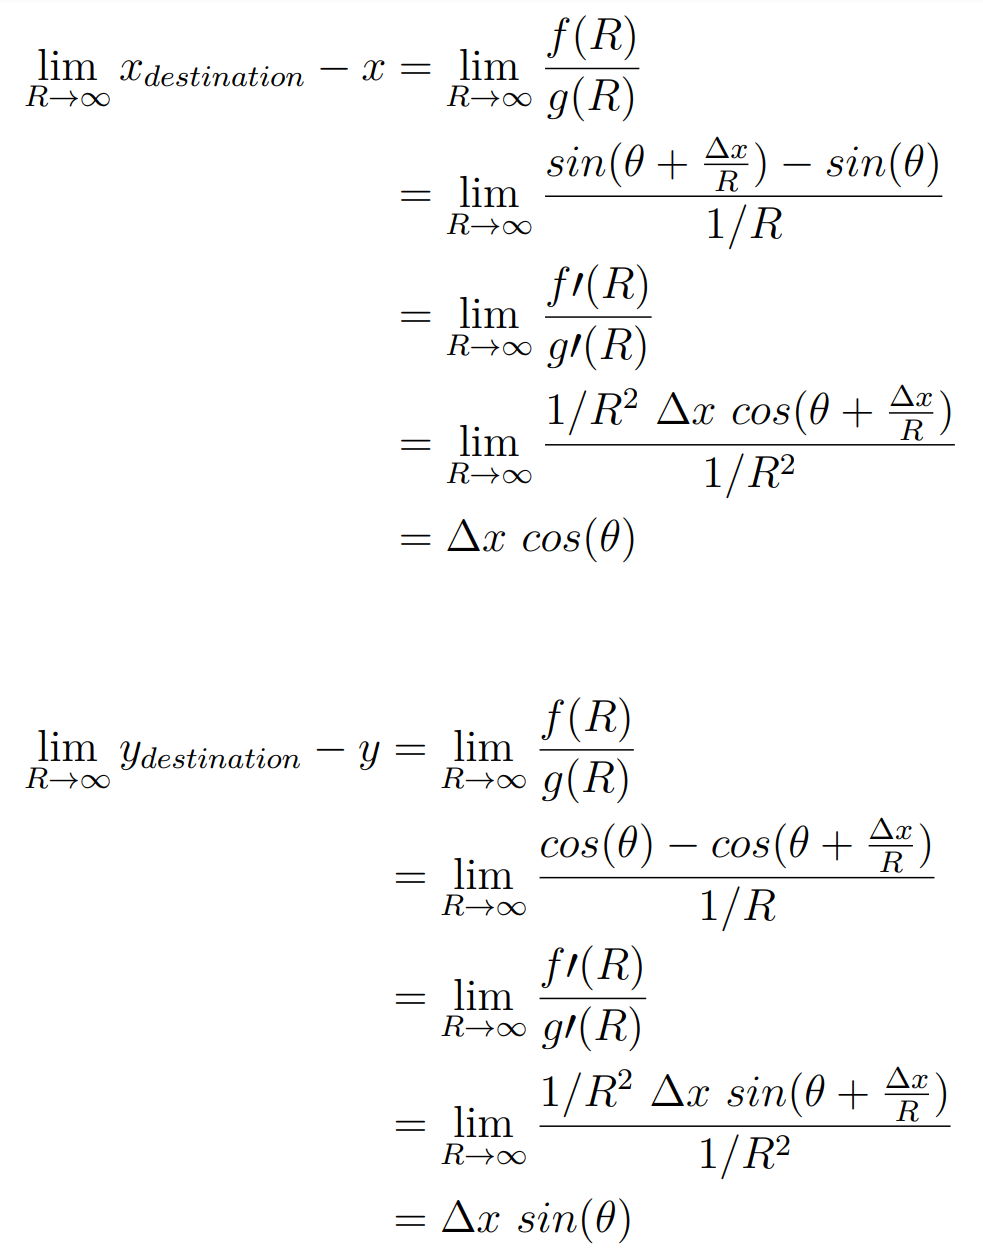

To calculate the boundary curves, the function [calculateSteeringReachability](matlab:matlab.desktop.editor.openAndGoToLine(which('ReachabilityAnalysis.m'),  getFunctionLineNr('calculateSteeringReachability'));) is used.

# Reference Trajectory Generation

## Local Trajectory Planner

### Plan Reference Trajectory

The purpose of the [LocalTrajectoryPlanner](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner\LocalTrajectoryPlanner.m')) is to plan a reference trajectory for the ego vehicle to either follow the lane or to execute a lane changing maneuver. For a lane changing command the command is associated with the time in which the lane change should be fulfilled.  If there is no lane changing command (*changeLaneCmd *= 0), the reference is to stay on the current lane. In this case, no reference trajectory needs to be generated because the reference (Stanely: the point on the center of the lane which is closest to the the front axle's center/ Pure Pursuit: sampled waypoints ahead on the center of the lane) is already defined by the road geometry (follow center of right or left lane). If there is a command, a lane changing trajectory (one for each Frenet and Cartesian coordinates) for the transfered duration is calculated. The lane changing trajectory is stored and will be deleted once the ego vehicle has passed the last element of the trajectory. (planReferenceTrajectory)

### Trajectory Generation

There is the possibility to generate either a longitudinal trajectory (following the current lane) or a lane changing trajectory (switch to the opposite lane) by using the class [TrajectoryGeneration](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner\TrajectoryGeneration.m')). The trajectory generation is based on the equations of motion for a double integrator model with a constant acceleration. The properties of a Frenet and Cartesian trajectory are defined in the classes [FrenetTrajectory](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner\FrenetTrajectory.m')) and [CartesianTrajectory](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner\CartesianTrajectory.m')) which are both subclasses of [Trajectory](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner\Trajectory.m')).

## Coordinate Transformations

There exist transformation funcions to go from Cartesian to Frenet coordinates and vice versa.

### Cartesian2Frenet

For the [Cartesian2Frenet](matlab:open('./Vehicle Functions\Helper Functions\Cartesian2Frenet.m')) transformation, the inputs are the position $[x,y]$ in the global Cartesian coordinate system and the road geometry. The outputs are the $s$ and $d$ Frenet coordinates.

### Frenet2Cartesian

For the [Frenet2Cartesian](matlab:open('./Vehicle Functions\Helper Functions\Frenet2Cartesian.m')) transformation, the inputs are he $s$ and $d$ Frenet coordinates and the outputs are the position $[x,y]$ in the global Cartesian coordinate system and the orientation of the road at that point.

## Derivation of a minimum jerk trajectory

--> From MOBATSim

The trajectory generation for lane-changing is based on a minimum lateral jerk for the vehicle. The passenger comfort is often parametrized as the smoothness of the lane-changing maneuver, which is the third derivative of the lateral displacement. If the lateral displacement of the vehicle from the reference lane is specified by the variable $d(t)$ as in the Frenet Frame, then the lateral jerk is:


$$\dddot d(t)=\frac{d^3(d(t))}{dt^3}$$


Now let us minimize the squared sum of the lateral jerk along the vehicle's trajectory. The cost function $J$ to be minimized becomes:


$$J(d(t))=\frac{1}{2}\int _{t_i} ^{t_f} \dddot d(t)^2dt
$$


where $t_i
$ and $t_f$ are the starting time and the ending time of the trajectory. The constant $\frac{1}{2}$ in front is only for mathematical convenience otherwise it has no significance.

We assume that after changing its lane, the vehicle keeps driving on the new lane without any further movement. This way, we can set the boundary conditions at the beginning and at the end of the trajectory:


$$\dot d(t_i)=\dot d(t_f) =  \ddot d(t_i)=\ddot d(t_f)=0$$


Now we need to derive the order of the polynomial that resembles the trajectory.

### Calculus of the Variations

We refer to the technique called calculus of the variations to find the minimum of a functional. Please note that our cost function $J$ was also a function the lateral displacement over time $d\left(t\right)$, therefore we need to define a variation function that depends on time $\eta(t)$. Let us impose a similar set of boundary conditions for the variation, which means that it smoothly goes away at the boundaries, i.e., at the beginning and end of the trajectory:

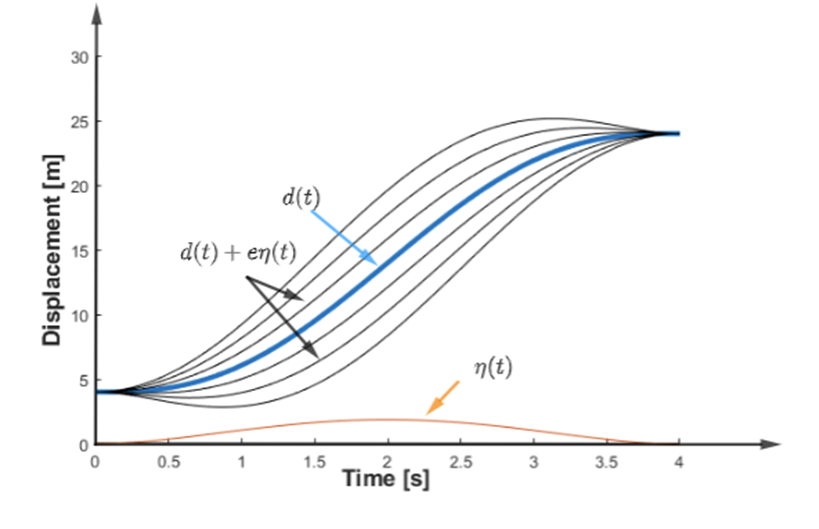


$$\eta(t_i)=\eta(t_f)=0
\\ \dot \eta(t_i)=\dot \eta(t_f)=0
\\ \ddot \eta(t_i)=\ddot \eta(t_f)=0$$


To minimize $J(d(t))$, we first replace $d(t)$by a variation $d(t)+\epsilon\eta(t)$ where $\varepsilon$ is a very small real number close to zero $d(t) \mapsto d(t)+\epsilon\eta(t)$:


$$J(d+e\eta)=\frac{1}{2}\int^{t_f}_{t_i}(\dddot d +e\dddot\eta)^2dt$$


We know that the functional $J$ has a minimum at $\epsilon =0$ and then we differentiate the cost function according to $\epsilon$ and replace it with zero.


$$ \frac{dJ(d+\epsilon\eta)}{\epsilon}=\int^{t_f}_{t_i}(\dddot d +e\dddot\eta)\dddot \eta dt
$$



$$\frac{dJ(d+\epsilon\eta)}{\epsilon} \big| _{\epsilon=0} =\int^{t_f}_{t_i}\dddot d\ \dddot\eta\ dt$$


Using integration by parts, we can rewrite this integral as:


$$\int ^{t_f}_{t_i}\dddot d \ \dddot \eta \ dt=  \dddot d \ \dddot \eta \big| ^{t_f}_{t_i} -\int^{t_f}_{t_i} \ddot \eta d^{(4)}dt=-\int ^{t_f}_{t_i} \ddot \eta d^{(4)}dt$$


Continuing the integration by parts:


$$\int ^{t_f}_{t_i} d^{(5)}  \dot \eta dt=   d^{(5)} \eta \big| ^{t_f}_{t_i} -\int ^{t_f}_{t_i}  \eta d^{(6)}dt=-\int ^{t_f}_{t_i}  \eta d^{(6)}dt$$


The final integral:


$$\frac{dJ(d+\epsilon \eta)}{\epsilon} \big |_{\epsilon=0}=-\int^{t_f}_{t_i}\eta d^{(6)}dt =0$$


The above property must hold true for any function $\eta(t)$, and therefore we have the fact that $d^{(6)}=0$, which means that function $d(t)$should have its sixth derivative equal to zero to have a minimum jerk function. $d(t)$has the general form of:


$$d(t)=a_0+a_1t+a_2t^2+a_3t^3+a_4t^4+a_5t^5$$


with the first and second derivatives, namely lateral speed and lateral acceleration as:


$$\dot d(t)=a_1+2a_2t+3a_3t^2+4a_4t^3+5a_5t^4$$



$$\ddot d(t)=2a_2+6a_3t+12a_4t^2+20a_5t^3$$


### Reference

Kyriakopoulos, K. J., & Saridis, G. N. (1991). Minimum jerk trajectory planning for robotic manipulators. *Cooperative Intelligent Robotics in Space*, *1387*, 159. [https://doi.org/10.1117/12.25421](https://doi.org/10.1117/12.25421)

## Calculate Trajectory for Lane Changing

To calculate the trajectory for lane changing, the function [calculateLaneChangingTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('calculateLaneChangingTrajectory'));) is used.

To calculate the trajectory for lane changing, first, the initial $d_{i}, \ \dot d_{i}, \ \ddot d_{i}$  and final conditions $d_{f}, \ \dot d_{f}, \ \ddot d_{f}$ need to be set. For going from the right to left lane the initial lateral displacement can be set to $d_{i} = 0$ (right lane) and the final lateral placement can be set to $d_{f} = 3.7$ (left lane). Accordingly, also the conditions for going from the left to the right lane can be set ($d_{i} = 3.7, \ d_{f} = 0$). For both of these maneuvers the other conditions will be set to zero: $\dot d_{i}, \ \ddot d_{i}, \ \dot d_{f}, \ \ddot d_{f} = 0$. Using the minimum jerk function $d(t)$ in its general form and the first and second derivatives $\dot d(t)$and $\ddot d(t)$ results in 6 equations, when considering the six boundary conditions. Also there are 6 unknown variables for the coefficients $a_0 , ..., a5$ describing the minimum jerk function. By utilising the *linsolve *command, these 6 coefficents and thus the minimum jerk trajectory in the lateral direction $d(t)$ for a specific maneuver and its derivatives can be calculated.

As shown in the figure, the longitudinal $s-$coordinate along the road is different from the $s_{curve}-$coordinate along the lane changing path:

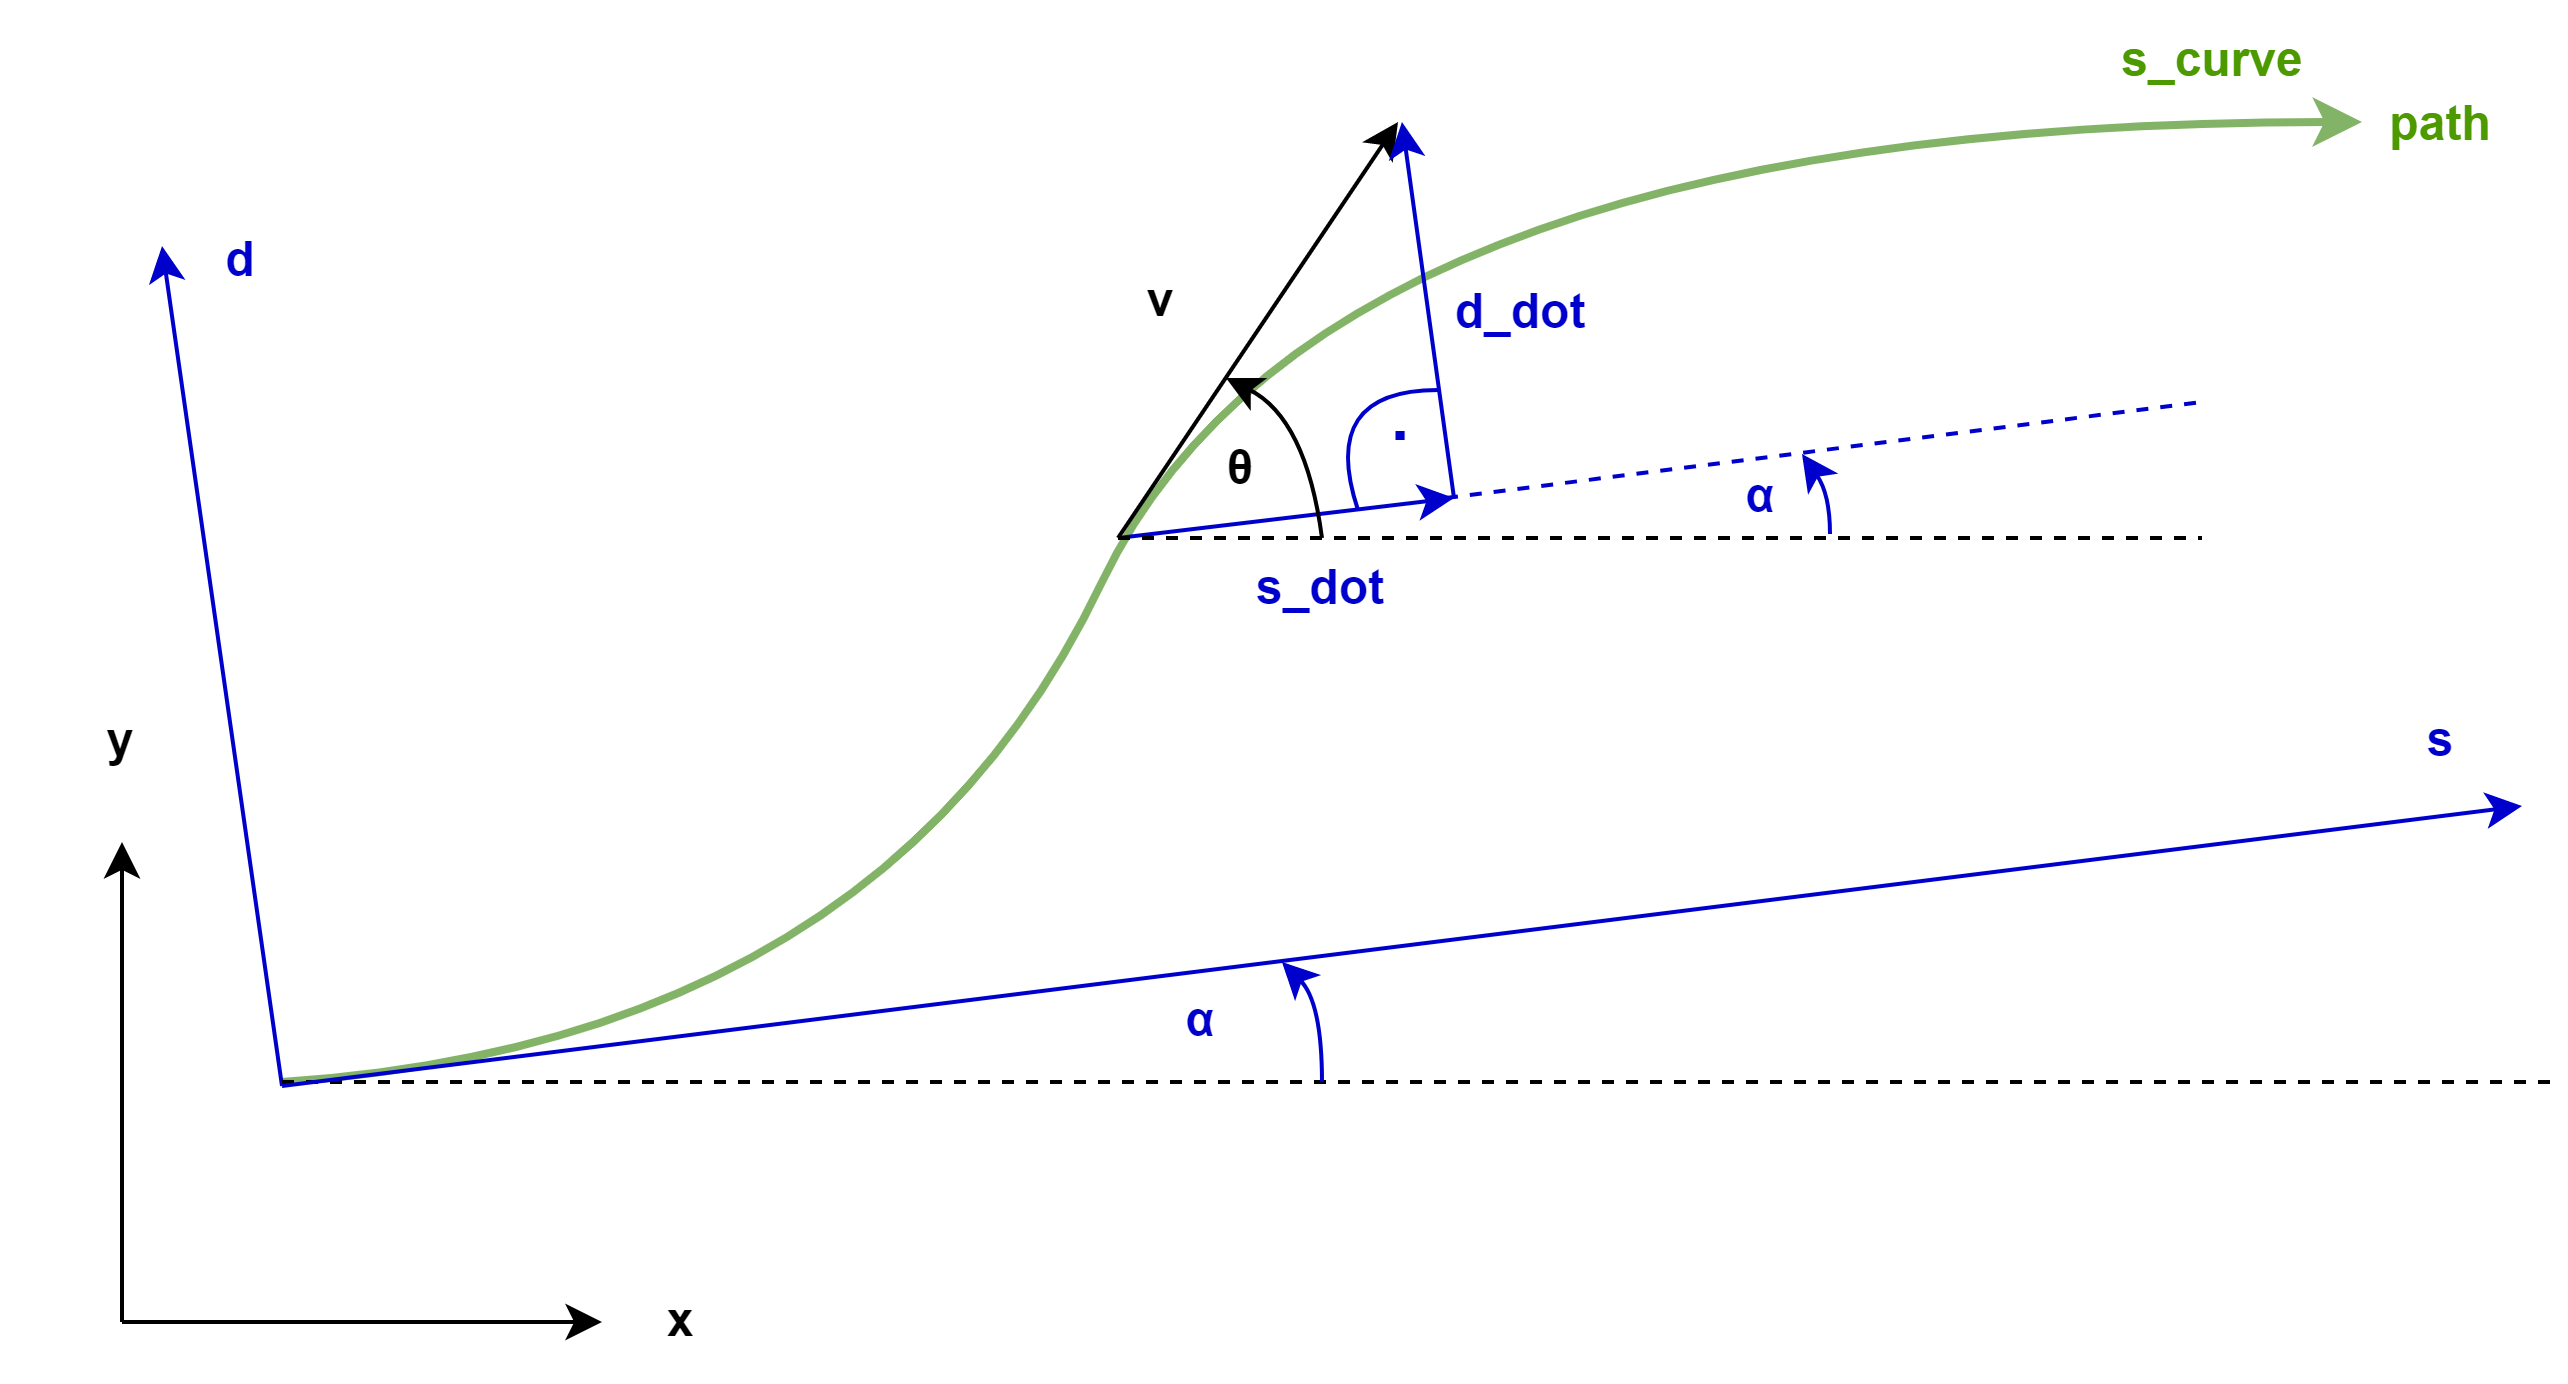

$s(t)$ can be found by integrating the speed profile in the longitudinal road direction $\dot s(t)$:


$$s(t) = \int _{t_i} ^{t_f} \dot s(t)\ dt
$$


The forward velocity $v$ of the vehicle as defined in the Kinematic Bicycle Model, can be decomposed into the velocity $\dot s$ along the road and the velocity $\dot d$ perpendicular to the road. $\dot d$ is given by the minimum jerk trajectory $\dot d(t)$ and also $v$ is specified. Thus, $\dot s$ can be determined:

    
$$\dot s = \sqrt{v^2 - \dot d^2}$$


By using the [Frenet2Cartesian](matlab:open('./Vehicle Functions\Helper Functions\Frenet2Cartesian.m')) coordinate transformation function, the lane changing points in Cartesian coordinates can be found. Also, the road orientation $\alpha$ at each lane changing point is calculated. As seen in the figure the reference orientation $\theta$ according to the lane changing path at each point is:


$$tan(\theta - \alpha) = \frac{\dot d}{\dot s} \\
\theta = atan2(\dot d, \ \dot s) + \alpha$$


# Space Discretisation

Also during initialisation, the continiuous road will be divided into discrete cells ([discretiseContinuousSpace](matlab:open('./Vehicle Functions\Helper Functions\discretiseContinuousSpace.m'))):

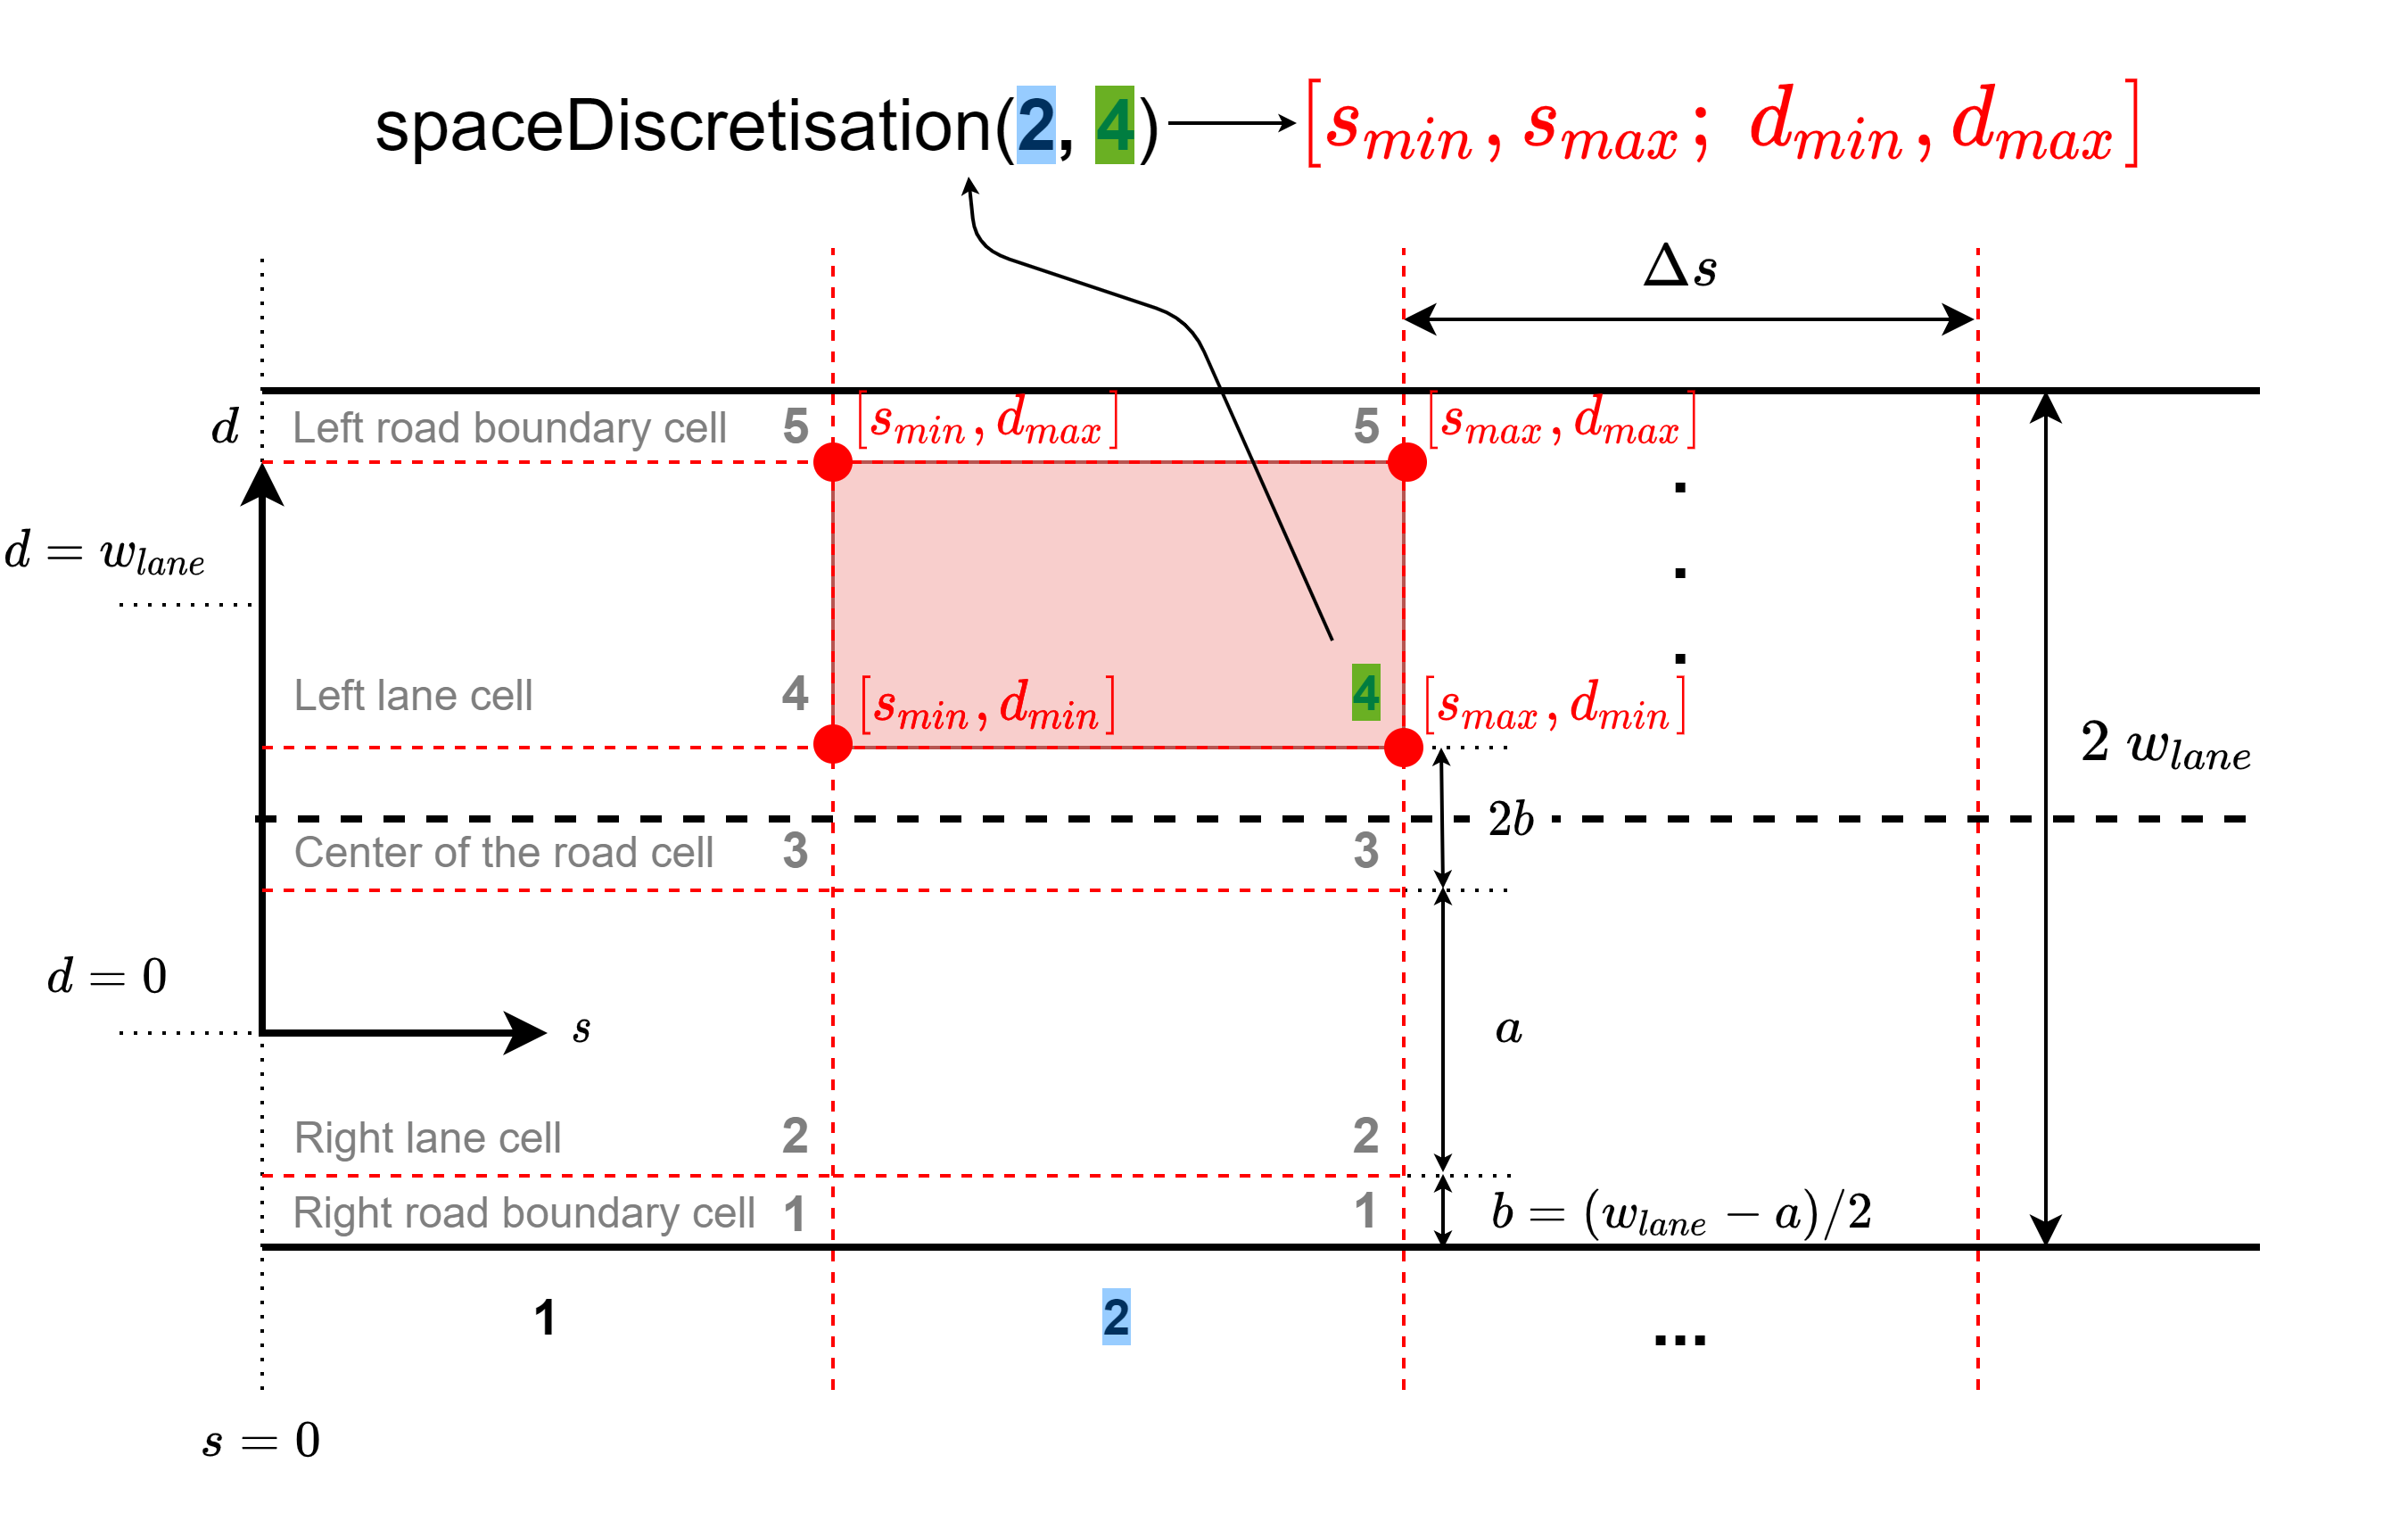

As the figure shows, the road's length ($s$-coordinate) is divided into equal sized parts $\Delta s$ (represented by $idx_{row}$). The road's width is divided into different sized parts. So for each $\Delta s$, 5 discrete cells are created (represented by $idx_{col}$):

- Right road boundry cell ($idx_{col} = 1$)

- Right lane cell ($idx_{col} = 2$)

- Center of the road cell ($idx_{col} = 3$)

- Left lane cell ($idx_{col} = 4$)

- Left road boundry cell ($idx_{col} = 5$)

Like this, the second left lane cell on the road e.g. is represented by $idx_{row} = 2, \ idx_{col} = 4$ (highlighted in red).

To specify the size of the cells, the cell's length $\Delta s$ and the width of the lane cells $a$ will be specified. By doing so, the variable $b$ can be calculated to define the width of the road boundary cells and the center of the road cell:

 
$$b = \frac{w_{lane}-a}{2}$$


This follows from:


$$a + 2b = w_{lane}$$


The continuous boundaries $[s_{min}, s_{max}; d_{min}, d_{max}]$ of each cell are stored in the cell array structure *spaceDiscretisation*:

prepare_simulation();
spaceDiscretisation;

Because Frenet coordinates are used, the discretisation also easily works for curved roads.

## Discrete to Continuous

To get the continuous boundaries $[s_{min}, s_{max}; d_{min}, d_{max}]$ of a discrete cell, the function [Discrete2Continuous](matlab:open('./Vehicle Functions\Helper Functions\Discrete2Continuous.m')) can be used. The inputs are the structure *spaceDiscretisation *and the row and column index $idx_{row}, \ idx_{col}$ that represents this cell.

## Continuous to Discrete

The function [Continuous2Discrete](matlab:open('./Vehicle Functions\Helper Functions\Continuous2Discrete.m')) takes the *spaceDiscretisation* and a Frenet trajectory as an input. The output is a discrete trajectory defined by the class [DiscreteTrajectory](matlab:open('./Vehicle Functions\DecisionMaking\DiscreteTrajectory.m')).

### Discrete Trajectory

A discrete trajectory is a sequence of discrete cells that the vehicle traverses while following a specified continuous trajectory. The vehicle enters and exits each cell at a specific time. A discrete trajectory contains the following properties:

The property *cells *contains the row and column indexes which lead to each discrete cell. The property *states *contain a specific label for each of the discrete cells. The property *entranceTimes *stores the times of when the vehicle enters each of the cells and the property *exitTimes *stores the times of when the vehicle exits each of the cells.

# Decision-Making

To plan the next maneuver, the ego vehicle needs to decide for one of the tree driving modes and whether to stay on the current lane or to change to the opposite lane. There exist two options for choosing what the next decision will be. The first option is a rule-based design for the discrete planner ([DiscretePlannerManual](matlab:open('./Vehicle Functions\DecisionMaking\Planner\DiscretePlannerManual.m'))). It can be used by specifing the argument 'planner' as 'MANUAL' when preparing the simulation:

prepare_simulation('planner', 'MANUAL');

The other existing option is to use a formal designed discrete planner ([DiscretePlannerFormal](matlab:open('./Vehicle Functions\DecisionMaking\Planner\DiscretePlannerFormal.m'))) for the simulation. It can be used by specifing the argument 'planner' as 'FORMAL' when preparing the simulation:

prepare_simulation('planner', 'FORMAL');

Both of them are subclasses of [DecisionMaking](matlab:open('./Vehicle Functions\DecisionMaking\Planner\DecisionMaking.m')).

## Rule-Based Design

The rule-based design only takes the current situation into account. It evaluates the current states of the vehicles involved in the driving scenarion. After this static evaluation, a decision is made by following simple rules which are defined by using if-else statements. Because of its simplicity, the rule-based design only needs very few computational ressources.

For the rule-based design ([DiscretePlannerManual](matlab:open('./Vehicle Functions\DecisionMaking\Planner\DiscretePlannerManual.m'))), different states are defined which represent a concrete driving situation. Furthermore, it is necessary to define transitions and transition conditions to go from one state to another. To avoid ambiguities, it is important that for the active state, only one transition which will lead to the next state can be activated at the same time. Finally, for each transition there is an output command, which is executed before going to the following state. The following figure shows the state diagram:

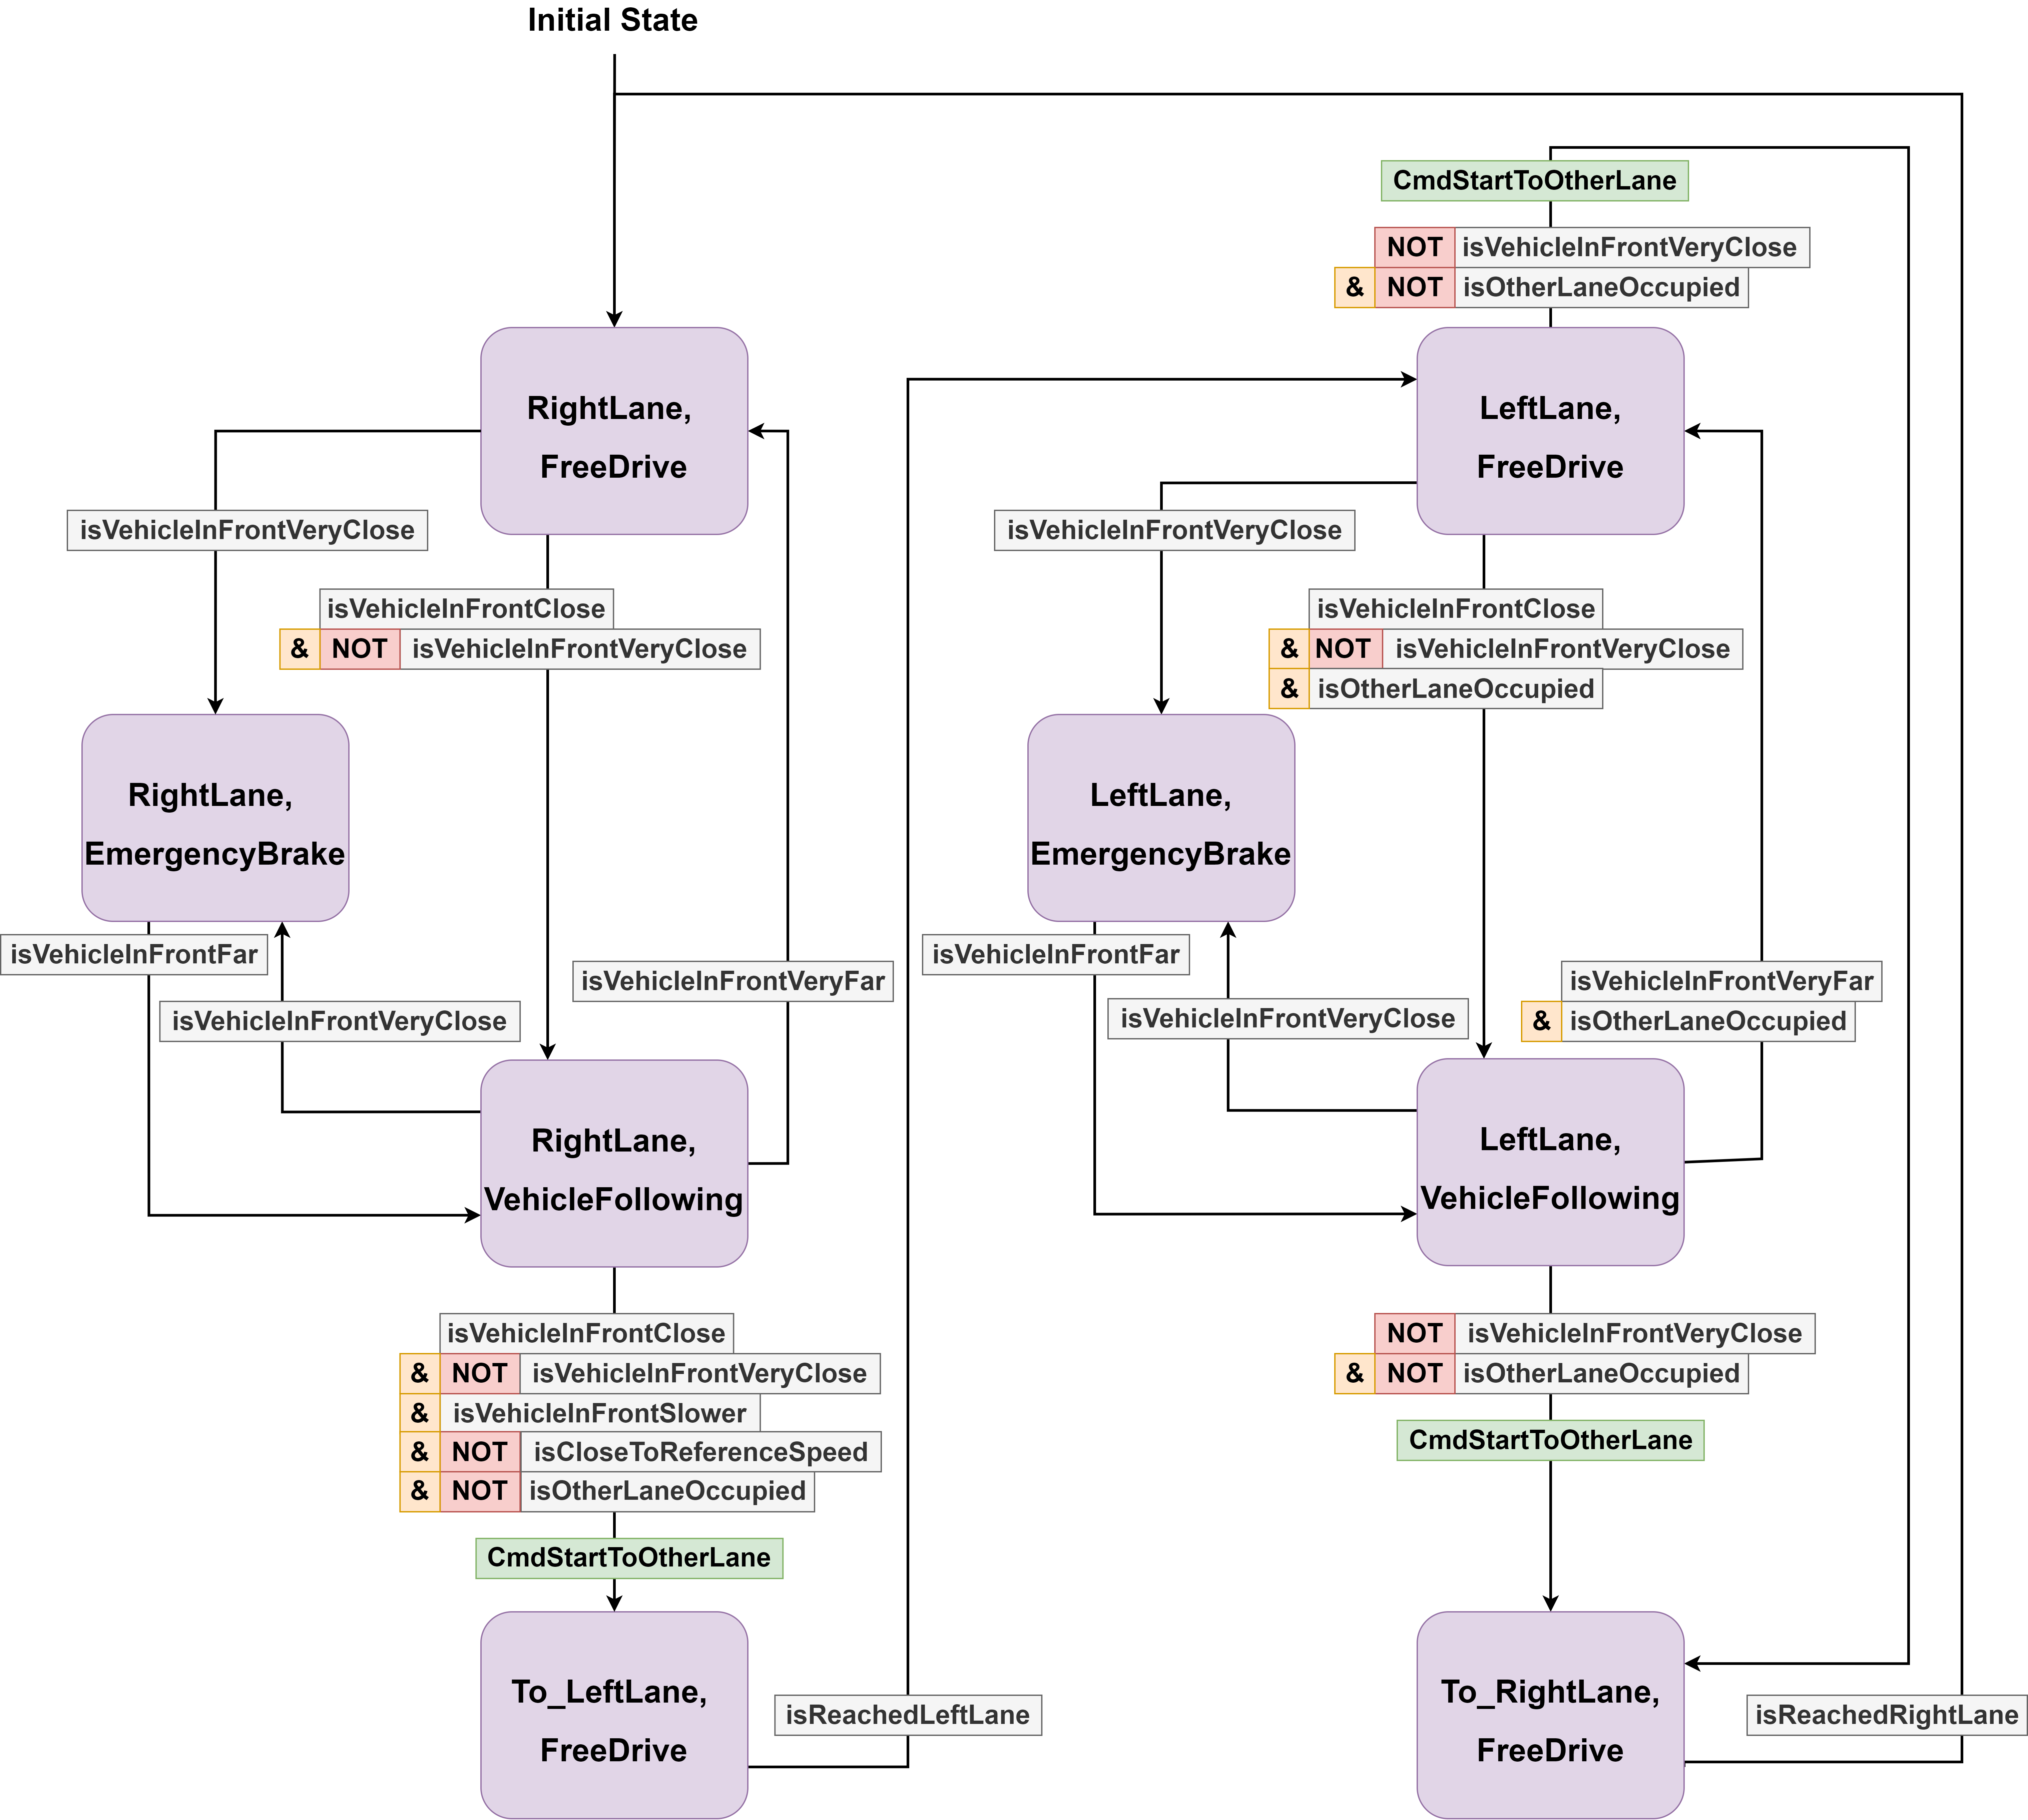

States are highlighted in purple. The arrows going from state to state represent the transitions. The transition conditions are highlighted in grey. A condition can be negated by using the NOT-operator (red).  Several conditions can be connected by AND-operators (orange). An output command is highlighted in green.

For reasons of clarity, transitions to the same state are not shown in the diagram. This transition is activated, when none of the other transitions are being activated. Also, only output commands to change the lane are shown in the diagram. If there is no output command on a transition in the diagram, the output command is to stay on the same lane.

Transition functions (LINK) with a boolean output (true or false) are defined to represent the transition conditions.

## Formal Design

For the formal design, a tree-based approach is used. The tree's root node represent the current situation (current state of the ego vehicle and the other vehicles). The formal design defines a [State](matlab:open('./Vehicle Functions\DecisionMaking\State.m')) by using the following properties:

Other than the rule-based design, the formal design also takes possible future situations into account. The [DiscretePlannerFormal](matlab:open('./Vehicle Functions\DecisionMaking\Planner\DiscretePlannerFormal.m')) multiple times within one time horizon, which allows to replan in case bad assumptions were made.

### Decision Generation

To generate different decisions for a given time horizon, the class [DecisionGeneration](matlab:open('./Vehicle Functions\DecisionMaking\DecisionGeneration.m')) can be used. For the current ego state, the following maneuvers are considered (calculateDecisions_Ego):

- **Keep Lane **- driving mode: **Free Drive**: Generate straight trajectories for different constant accelerations: $1 \frac{m}{s^2} \leq a \leq a_{max}$

- **Keep Lane **- driving mode: **Vehicle Following**: Generate straight trajectories for different constant accelerations: $a_{min} \leq a \leq 0$

- **Keep Lane **- driving mode: **Emergency Brake**: Generate one straight trajectory for a constant emergency acceleration: $a_{emergency}$

- **Change Lane **- driving mode: **Free Drive**: Generate lane changing trajectories for different durations: $T_{min} \leq T_{LC} \leq T_{h}$

To limit the amount of trajectories that need to be generated, only some sampled values inside the limits from above are taken into account for the generation.

The formal design defines a [Decision](matlab:open('./Vehicle Functions\DecisionMaking\Decision.m')) by using the following properties:

So each generated trajectory relates to a possible decision for the ego vehicle. Furthermore, similar decisions are also generated for the other vehicles. Other than for the ego vehicle, only two trajectories are generated for each other vehicle (calculateDecisions_Other)(getDecisionForKeepLane_Other):

- **Keep Lane**: Generate two straight trajectories for the minimum possible acceleration $a_{min}$ and the maximum possible acceleration $a_{max}$

These **two trajectories** are related to **one single decision** with two possible future states (minimum and maximum possible future state). This one single decision should represent the worst possible actions that one other vehicle could take. Therefor, one discrete trajectory, that considers all the worst possible cases is created by using the two generated trajectories for $a_{min}$ and $a_{max}$ (calculateDiscreteTrajectory_Other):

First, the discrete trajectories for the minimum (trajectory with constant acceleration $a_{min$) and maximum (trajectory with constant acceleration $a_{max}
$)) case are generated. Then, the goal is to combine them, to represent the worst case scenarios. We know, that the vehicle cannot enter the cells from the trajectories earlier than specified by the entrance times for the maximum case. Thus, we can set this as the lower limit for the entrance time to each cell. For the exit times, we know that the vehicle will not exit a cell later than the exit time specified for the minimum case. Like this, we can also set a upper limit for the exit time to a cell. However, we can only set an exact upper limit  for cells that are covered by the minimum case. Because the vehicle could potentially stop at any of the cells after the last one of the minimum case trajectory, the upper limit for those cells is set to infinity:

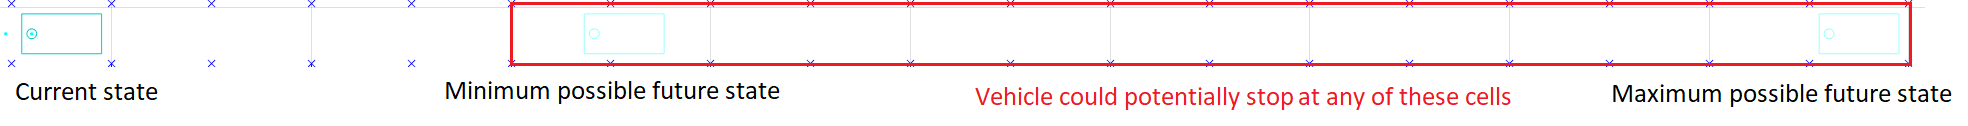

Like this, the entrance and exit time for each cell can be conservatively limited according to the worst case scenario. Thus, a single discrete trajectory can be defined.

### Safety Assessment

To assess the safety of each ego decision, the discrete trajectories corresponding to the decisions are compared to the other vehicles' worst case discrete trajectories. The safety comparing two discrete trajectories can be checked (isSafeTransitions):

If there are no overlapping cells, safety should be guaranteed. If there are overlapping cells, the entrance and exit times need to be compared to make an assessment regarding safety (isSafeTemporalDiff):

In this case, safety should be guaranteed, if the ego vehicle either:

- Enters a cell after the other vehicle has left this cell

- Exits a cell befor the other vehicle has entered this cell

### Tree Search

To select the next decision for the ego vehicle tree search algorithms are being used ([TreeSearch](matlab:open('./Vehicle Functions\DecisionMaking\TreeSearch.m'))).

#### Building the Tree

Starting with the initial situation (initial states for ego vehicle and other vehicles) which corresponds to the tree's root node , the predefined decisions for the ego vehicle and the other vehicles can be generated. This results in possible future states and thus also in new nodes in the tree. By generating new decisions for these future states, the tree can be further expanded. The deeper the tree gets, the further we will look into the future. The step from a certain situation to a future situation after one time horizon is defined as one depth in the tree.

#### Depth-First Search

To expand the tree, different strategies can be pursued. For this work, we will use the strategy of depth-first search. This means, that one path in the tree will be expanded deeper and deeper until reaching a specified depth limit, before branching to another path.

#### Static Evaluation 

When reaching the predefined depth limit, the state at this depth limit can be statically evaluated. The class [Values](matlab:open('./Vehicle Functions\DecisionMaking\Values.m')) distinguishes between a safety and a liveness value of a state. The higher the safety value, the less a chance of collision between the ego vehicle and another vehicle becomes. The safety value corresponds to the number of unsafe states determined by the safety assessment. The number of unsafe states are counted negatively with $0$ being the safest and $- \infty$ being the unsafest. The safety of earlier decisions in the tree (lower depth) are prioritised. This can be achived by introducing a discount factor $\gamma \in [0,1]$ :

Furthermore, a state can be evaluated according to its liveness. The liveness is a measure for the progress of reaching a predefined goal. So a higher liveness value corresponds to reach the goal faster than for a lower liveness value. The livenss value of a state is defined as:

The total value of a state consists of both the safety and the liveness value with the safety being prioritised. Therefor, a layered approach is used. For comparing (LINK) two values, first, the safety value will be compared. Only if the two safety values are equal, a comparision of the liveness values is necessary as shown in the example:

#### Minimum Violation Planning (MVP)

In case none of the decisions is considered safe (safety value < 0), the next decision should be chosen according to the sequence of actions leading to the maximum safety value (minimum violation).  This corresponds to achieve as few overlapping unsafe states as possible. Earlier violations are prioritised (violations earlier in time are worse than later violations later in time).

#### Minimax Algorithm 

To find choose the best decision inside the tree, the minimax algorithm is used. Therfore, the ego vehicle is considered as the maximising (*MAX*) player (planMaxManeuver), trying to maximise both safety and liveness value and the other vehicles are considered as minimising (*MIN*) players (planMinManeuver), trying to minimise the value. 

The following figure shows the generated tree for a depth limit of 2. Green edges represent possible decisions for the ego vehicle and red edges represent decisions, or more precisely, possible future state combinations for the other vehicles. Possible future states are calculated according to the minimum and maximum case (see Decision Generation). These possible future states lead to a number of possible future combinations/situations for the other vehicles (in this case {[minFutureState minFutureState], [minFutureState maxFutureState], [maxFutureState minFutureState], [maxFutureState maxFutureState]}) (getStateCombinations):

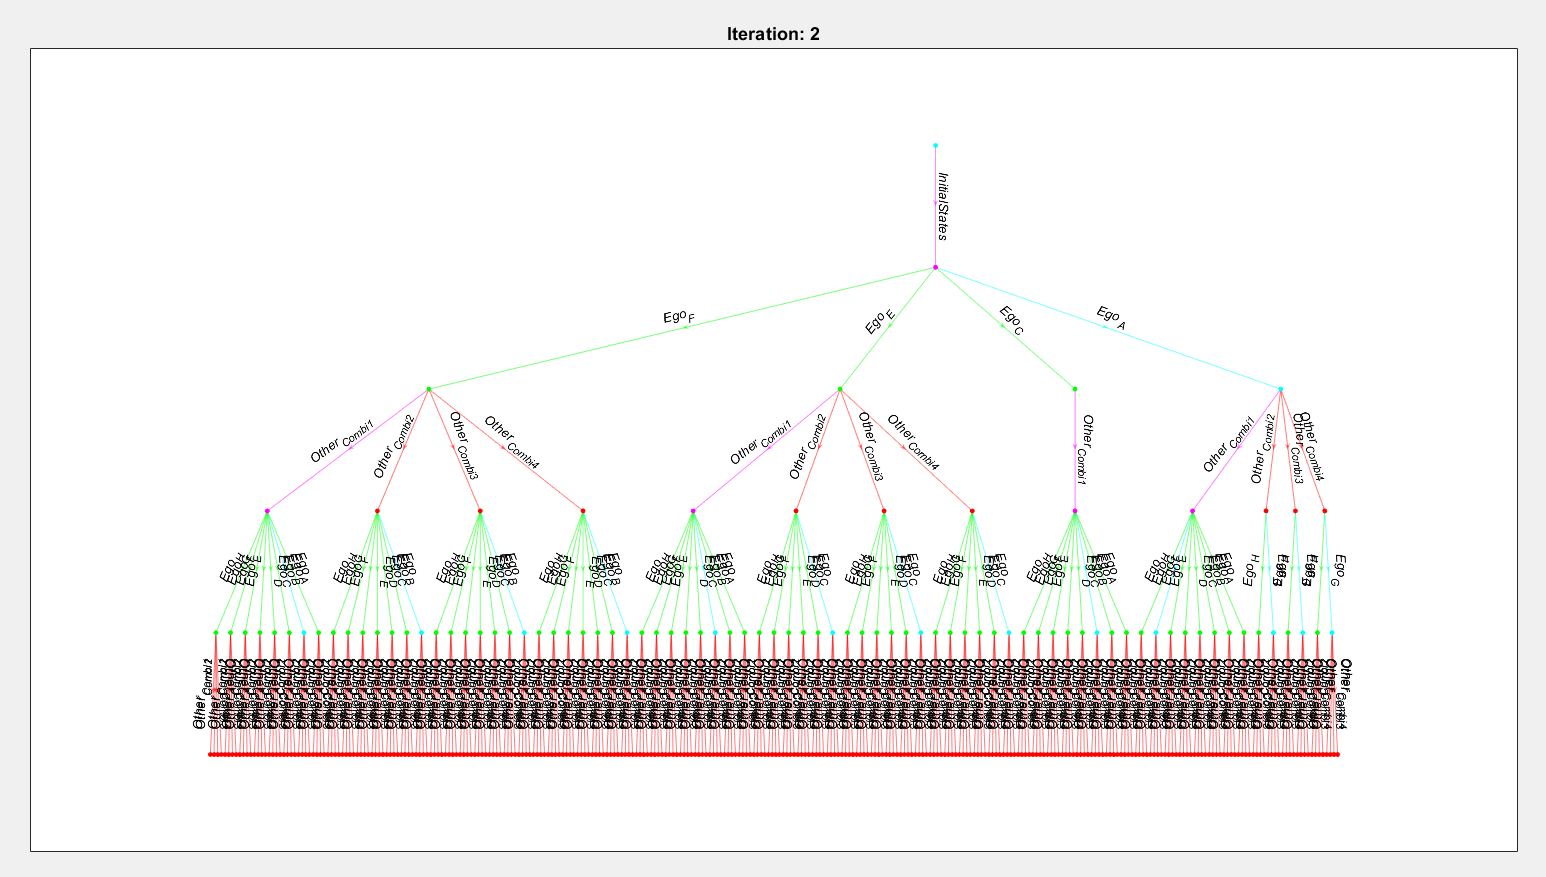

After the static evaluations at the end of the tree, the ego vehicle, will select the decision, that will lead to the maximum value (highlighted in teal). This value gets propagated to the parent node. Then, the minimising state combination for the other vehicles will be selected. This means, that for the other vehicles, we will choose the state combination, which will lead to the lowest value (of preciously selected maximum values). This combination is highlighted in pink. This procedure goes on and the min/max values are propagated up the tree until the root node is reached. At the end of the algorithm, the root node should contain the maximum possible value inside the tree for the ego vehicle when considering an adversarial behaviour of the other vehicles, that are trying to minimise the value whenever possible. Also the decisions leading to this best possible value can be traced back by following the sequence of alternating teal and pink edges.

#### Iterative Deepening

To have the possibility to get an answer (next planned decision) at any desired time (even when not running the algorithm until the end), iterative deepening is used. This means, that the algorithm will be run for several increasing depth limits. The first iteration starts with a depth limit of 1 and will lead to a first result. Then the algorithm will rerun for a depth limit of 2, to find an even better result by looking deeper into the future. This goes on until a predefined ultimate depth limit is reached or until a predefined limit time has expired. Like this, whith each iteration, the result will improve. Also, there will be an answer available at any time while executing the algorithm.

# Collision Detection

For [collision detection](matlab:open('./Vehicle Functions\CollisionDetection.m')) --> MOBATSim

The collision detection algorithm works by checking if any two vehicles have a geometrical intersection. As the vehicle positions, orientations and sizes are known, sizes being rectangles, the problem is reduced to checking corner points of a rectangle in the polygon of another rectangle. Since every vehicle is checked to each other, once a collision is detected, namely one or more corners of a rectangle happen to be inside another rectangle, both vehicles' collision properties are set to collide.

The checking of two rectangles with one another happens only if the vehicles are close to each other. Otherwise, it is a waste of computational resources if two rectangles are very far from each other to be checked. The threshold value for checking between vehicles that are close enough is chosen according to the L2 norm of the corner points of the rectangle, as it would not be possible otherwise for two rectangles to coincide.

**Check for Collision **- `false`** // Collided **- `false`

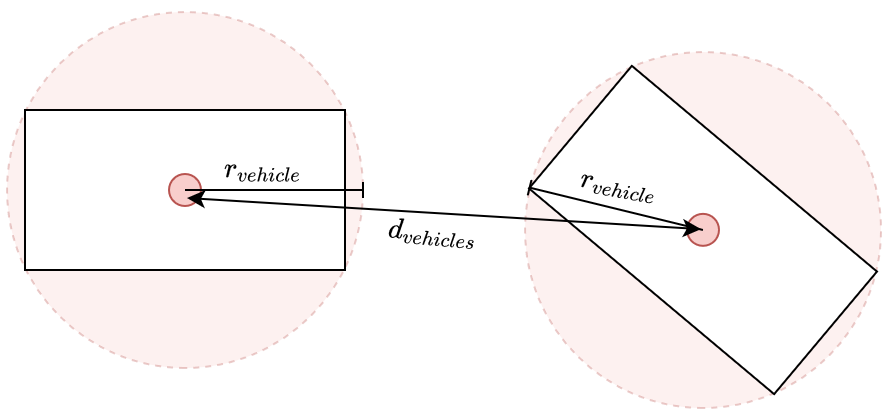

**Check for Collision **- `true`** // Collided **- `false`

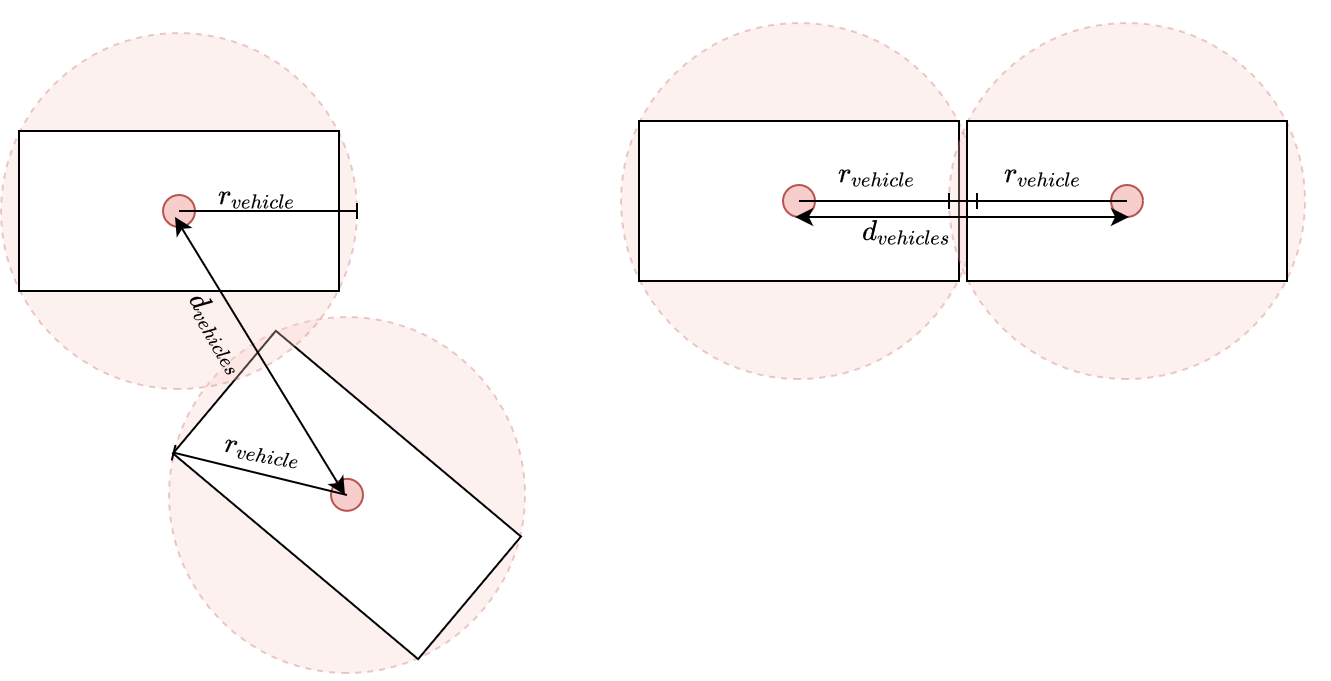

**Check for Collision **- `true`** // Collided **- true

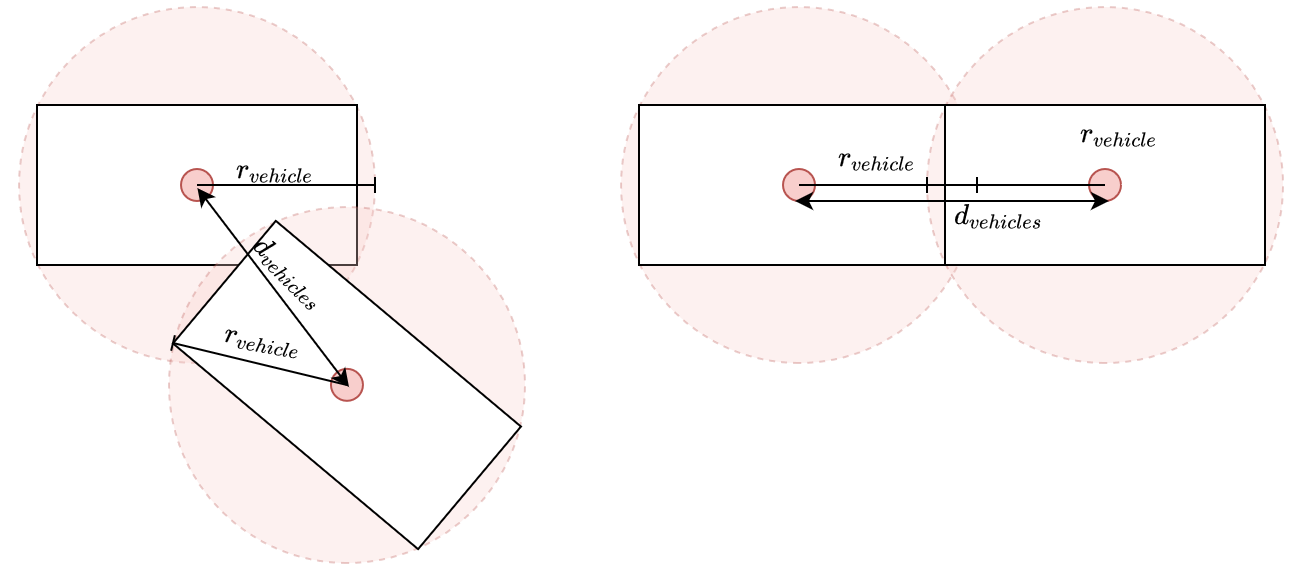

# Visualisation

For the [visualisation](matlab:open('./Visualisation\PlotDrivingScenario.m')) the MATLAB plotting function is used (alternatively a 3D animation can be used). 

When setting up the MATLAB system, first of all the road (1 in fugure)  and the space discretisation are plotted ([plotRoadLine](matlab:matlab.desktop.editor.openAndGoToLine(which('PlotDrivingScenario.m'),  getFunctionLineNr('plotRoadLine'));)) ([plotDiscreteSpace](matlab:matlab.desktop.editor.openAndGoToLine(which('PlotDrivingScenario.m'),  getFunctionLineNr('plotDiscreteSpace'));)). To represent the discrete cells, the boundries **[s_min, s_max; d_min, d_max]** are combined to draw the corner points (2) of each cell.

The procedure at every sample time step is as follows:

In the beginning, previous plots, that are not relevant anymore are deleted ([deletePreviousPlots](matlab:matlab.desktop.editor.openAndGoToLine(which('PlotDrivingScenario.m'),  getFunctionLineNr('deletePreviousPlots'));)). Then the vehicles and additional information are drawn. This includes:

- The ego (3a) and leading (3b) vehicle themselves ([plotVehicle](matlab:matlab.desktop.editor.openAndGoToLine(which('PlotDrivingScenario.m'),  getFunctionLineNr('plotVehicle'));)): To create the rectangle vehicle representation ([createRectangleVehicle](matlab:open('./Vehicle Functions\Helper Functions\createRectangleVehicle.m'))), the center of the vehicle has to be determined ([getVehicleCenterPoint](matlab:open('./Vehicle Functions\Helper Functions\getVehicleCenterPoint.m'))) because the vehicle's pose and body coordinate origin is according to the kinematic bicycle model (the center of the rear axle, which is represeted as a dot. This includes also the future predictions (4) for the leading vehicle according to the longitudinal reachability analysis. More vehicles can easily be added to be plot for visualisation.

- The vehicles' past poses (5) which results in a dotted line (traces).

- The planned trajectory (6) for the next few seconds (according to specified time horizon); For Pure Pursuit, also the next planned waypoints (7) are visualised.

- The ego vehicle's steering reachability (8)